clear;
clc;
close all;

% Lapso temporal
t = linspace(0, 3e4, 1e6);

% Constantes (SSO)
mu = 3.986004418e14;
J2 = 1.082635854e-3;
R = 6378.137e3;
a = 7211.54e3;
e = 0.01;
n = sqrt(mu ./ a.^3);
INC     = deg2rad(98.7);
Omega   = deg2rad(0);
omega   = deg2rad(30);
theta_0 = deg2rad(0);

% Condiciones iniciales
[posECI, velECI] = OE2ECI(mu, a, e, INC, Omega, omega, theta_0);
x0I = posECI(1);
y0I = posECI(2);
z0I = posECI(3);
dx0I = velECI(1);
dy0I = velECI(2);
dz0I = velECI(3);
x0   = 0;
y0   = 0;
z0   = 0;
dx0  = 0;
dy0  = 0;
dz0  = 0;

% Identidades trigonométricas
nt = n.*t;

% Constantes de la memoria
eta   = nt/2;
alpha1  =     omega +   theta_0;
alpha2  =   2*omega +   theta_0;
alpha3  =   2*omega + 3*theta_0;
alpha4  =     omega + 2*theta_0;
alpha5  =     omega + 3*theta_0;
alpha6  =     omega -   theta_0;


beta1   =       eta +    alpha1;
beta2   =     3*eta +  2*alpha1;
beta3   =       eta +  2*alpha1;
beta4   =       eta -  2*alpha1;
beta5   =     2*eta +    alpha1;
beta6   =     3*eta +    alpha1;
beta7   =    -  eta +    alpha1;
beta8   =   - 2*eta +    alpha1;

beta9   =     2*eta +    alpha2;
beta10  =     4*eta +    alpha2;
beta11  =   - 2*eta +    alpha2;

beta12  =    4*eta +    alpha3;
beta13  =    6*eta +    alpha3;
beta14  =  - 2*eta +    alpha3;

beta15  =      eta +    alpha4;
beta16  =    2*eta +    alpha4;
beta17  =    3*eta +    alpha4;
beta18  =    4*eta +    alpha4;
beta19  =    - eta +    alpha4;
beta20  =  - 2*eta +    alpha4;

beta21  =     2*eta +    alpha5;
beta22  =     4*eta +    alpha5;
beta23  =     6*eta +    alpha5;
beta24  =   - 2*eta +    alpha5;

beta25  =     2*eta +    alpha6;
beta26  =   - 2*eta +    alpha6;


tau1    =     2*eta +   theta_0;
tau2    =   - 2*eta +   theta_0;
o1      =       eta +     omega;
o2      =     2*eta +     omega;
o3      =     - eta +     omega;
o4      =   - 2*eta +     omega;
kappa_i = 3*cos(2*INC) + 1;

% Solución analítica
xB = (cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(Omega) - sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(INC).*sin(Omega)).*((640.*a.*n - 480.*a.*n.*cos(n.*t) - 2560.*a.*e.^2.*n + 3840.*a.*e.^4.*n - 2560.*a.*e.^6.*n + 640.*a.*e.^8.*n + 1920.*a.*e.^2.*n.*cos(n.*t) - 2880.*a.*e.^4.*n.*cos(n.*t) + 1920.*a.*e.^6.*n.*cos(n.*t) - 480.*a.*e.^8.*n.*cos(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*x0 + (160.*sin(n.*t).*a - 640.*sin(n.*t).*a.*e.^2 + 960.*sin(n.*t).*a.*e.^4 - 640.*sin(n.*t).*a.*e.^6 + 160.*sin(n.*t).*a.*e.^8)./(160.*a.*n.*(e.^2 - 1).^4).*dx0 + (320.*a - 320.*a.*cos(n.*t) - 1280.*a.*e.^2 + 1920.*a.*e.^4 - 1280.*a.*e.^6 + 320.*a.*e.^8 + 1280.*a.*e.^2.*cos(n.*t) - 1920.*a.*e.^4.*cos(n.*t) + 1280.*a.*e.^6.*cos(n.*t) - 320.*a.*e.^8.*cos(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*dy0 + (-(60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 120.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 960.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(160.*a.*n.*(e.^2 - 1).^4)).*t.*J2 + (-(60.*R.^2.*n - 60.*R.^2.*n.*cos(n.*t) - 30.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*cos(2.*INC + n.*t) - 90.*R.^2.*n.*cos(2.*INC - n.*t) + 180.*R.^2.*n.*cos(2.*INC) - 60.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0) - 60.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 15.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 15.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 10.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 10.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 120.*R.^2.*n.*cos(2.*omega + 2.*theta_0) + 90.*R.^2.*e.*n.*cos(- 2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 + n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 - n.*t) - 660.*R.^2.*e.^2.*n.*cos(2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*cos(2.*omega - n.*t) - 60.*R.^2.*e.*n.*cos(2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*cos(2.*omega + theta_0 - n.*t) - 40.*R.^2.*e.*n.*cos(2.*omega + theta_0 + 2.*n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - 3.*theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 25.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 80.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0) + 60.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 60.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC - theta_0 + n.*t) + 240.*R.^2.*e.^2.*n.*cos(2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega) - 70.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 - n.*t) + 40.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 2.*n.*t) - 50.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 3.*n.*t) - 120.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0) - 120.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0) - 240.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 240.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 10.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 25.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 25.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 640.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0) - 80.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0) + 330.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega + n.*t) + 330.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega - n.*t) + 30.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0 + n.*t) + 30.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 240.*R.^2.*e.*n.*cos(2.*omega + theta_0) + 480.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + n.*t) - 50.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 - n.*t) + 50.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 3.*n.*t) - 32.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 4.*n.*t) - 40.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0) - 40.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0))./(160.*a.*n.*(e.^2 - 1).^4)).*J2) - (sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(Omega) + cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(INC).*sin(Omega)).*((-(960.*a.*n.^2 - 3840.*a.*e.^2.*n.^2 + 5760.*a.*e.^4.*n.^2 - 3840.*a.*e.^6.*n.^2 + 960.*a.*e.^8.*n.^2)./(160.*a.*n.*(e.^2 - 1).^4)).*x0.*t + (960.*a.*n.*sin(n.*t) - 3840.*a.*e.^2.*n.*sin(n.*t) + 5760.*a.*e.^4.*n.*sin(n.*t) - 3840.*a.*e.^6.*n.*sin(n.*t) + 960.*a.*e.^8.*n.*sin(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*x0 + (160.*a.*n - 640.*a.*e.^2.*n + 960.*a.*e.^4.*n - 640.*a.*e.^6.*n + 160.*a.*e.^8.*n)./(160.*a.*n.*(e.^2 - 1).^4).*y0 + (-(640.*sin((n.*t)./2).^2.*a - 2560.*sin((n.*t)./2).^2.*a.*e.^2 + 3840.*sin((n.*t)./2).^2.*a.*e.^4 - 2560.*sin((n.*t)./2).^2.*a.*e.^6 + 640.*sin((n.*t)./2).^2.*a.*e.^8)./(160.*a.*n.*(e.^2 - 1).^4)).*dx0 + (-(480.*a.*n - 1920.*a.*e.^2.*n + 2880.*a.*e.^4.*n - 1920.*a.*e.^6.*n + 480.*a.*e.^8.*n)./(160.*a.*n.*(e.^2 - 1).^4)).*dy0.*t + (640.*sin(n.*t).*a - 2560.*sin(n.*t).*a.*e.^2 + 3840.*sin(n.*t).*a.*e.^4 - 2560.*sin(n.*t).*a.*e.^6 + 640.*sin(n.*t).*a.*e.^8)./(160.*a.*n.*(e.^2 - 1).^4).*dy0 + (-(720.*R.^2.*e.^2.*n.^3.*sin(2.*omega) + 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC - 2.*omega) - 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC + 2.*omega))./(160.*a.*n.*(e.^2 - 1).^4)).*t.^2.*J2 + (480.*R.^2.*n.^2 + 180.*R.^2.*n.^2.*sin(INC + omega + theta_0).^2 - 720.*R.^2.*e.*n.^2 + 180.*R.^2.*n.^2.*sin(- INC + omega + theta_0).^2 - 360.*R.^2.*n.^2.*sin(omega + theta_0).^2 - 720.*R.^2.*n.^2.*sin(INC).^2 + 360.*R.^2.*e.*n.^2.*sin(INC + omega + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(INC + omega + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(omega + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(- INC + theta_0./2 + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 360.*R.^2.*e.*n.^2.*sin(- INC + omega + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(- INC + omega + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + theta_0).^2 - 120.*R.^2.*e.^2.*n.^2.*sin(INC + omega + 2.*theta_0).^2 - 480.*R.^2.*e.^2.*n.^2.*sin(omega + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 - 720.*R.^2.*e.*n.^2.*sin(omega + theta_0./2).^2 - 240.*R.^2.*e.*n.^2.*sin(omega + (3.*theta_0)./2).^2 + 1920.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0).^2 - 240.*R.^2.*e.*n.^2.*cos(theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(INC + theta_0./2 + (n.*t)./2).^2 + 480.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0 + (n.*t)./2).^2)./(160.*a.*n.*(e.^2 - 1).^4).*t.*J2 + (140.*R.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) - 60.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 120.*R.^2.*n.*sin(n.*t) + 10.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 180.*R.^2.*n.*sin(2.*INC + n.*t) + 180.*R.^2.*n.*sin(2.*INC - n.*t) + 45.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0) + 45.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) + 30.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 70.*R.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 30.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 5.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 5.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*sin(2.*omega + 2.*theta_0) + 70.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0) + 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0) + 540.*R.^2.*e.*n.*sin(- 2.*INC + theta_0 + n.*t) + 540.*R.^2.*e.*n.*sin(2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.*sin(2.*INC + theta_0 - n.*t) - 1080.*R.^2.*e.^2.*n.*sin(2.*omega + n.*t) - 840.*R.^2.*e.^2.*n.*sin(2.*omega - n.*t) + 720.*R.^2.*e.*n.*sin(2.*INC - theta_0) - 120.*R.^2.*e.*n.*sin(2.*omega + theta_0 + n.*t) + 280.*R.^2.*e.*n.*sin(2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + theta_0 + 2.*n.*t) + 140.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 70.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + 10.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0) + 360.*R.^2.*e.*n.*sin(theta_0 + n.*t) + 120.*R.^2.*e.*n.*sin(theta_0 - n.*t) - 180.*R.^2.*e.*n.*sin(2.*INC - theta_0 + n.*t) + 1920.*R.^2.*e.^2.*n.*sin(2.*omega) + 960.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega) - 960.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega) + 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 3.*n.*t) + 90.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0) + 90.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0) - 360.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 210.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 360.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) + 10.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 320.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0) + 50.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0) - 480.*R.^2.*e.*n.*sin(theta_0) + 540.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega + n.*t) + 540.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega - n.*t) - 720.*R.^2.*e.*n.*sin(2.*INC + theta_0) + 60.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) + 60.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 - n.*t) - 10.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) - 180.*R.^2.*e.*n.*sin(2.*omega + theta_0) + 720.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) + 40.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + n.*t) + 20.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 84.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) + 14.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 4.*n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*J2) + sin(INC).*sin(Omega).*((8.*a.*n.*cos(n.*t) - 32.*a.*e.^2.*n.*cos(n.*t) + 48.*a.*e.^4.*n.*cos(n.*t) - 32.*a.*e.^6.*n.*cos(n.*t) + 8.*a.*e.^8.*n.*cos(n.*t))./(8.*a.*n.*(e.^2 - 1).^4).*z0 + (8.*sin(n.*t).*a - 32.*sin(n.*t).*a.*e.^2 + 48.*sin(n.*t).*a.*e.^4 - 32.*sin(n.*t).*a.*e.^6 + 8.*sin(n.*t).*a.*e.^8)./(8.*a.*n.*(e.^2 - 1).^4).*dz0 + (6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega))./(8.*a.*n.*(e.^2 - 1).^4).*t.*J2 + (48.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(omega).*sin(theta_0) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(omega) + 6.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(n.*t).*sin(omega) - 6.*R.^2.*e.*n.*sin(2.*INC).*sin(n.*t).*cos(omega) - 6.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 5.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*sin(omega) + 7.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*cos(omega) + 5.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*cos(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*sin(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*cos(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*cos(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(3.*n.*t).*sin(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(3.*n.*t).*cos(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(3.*n.*t).*cos(omega) - 7.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*sin(omega) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*sin(omega) - 3.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(3.*n.*t).*sin(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) - 18.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*cos(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega) - 56.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) - 28.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(omega).*sin(theta_0) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(theta_0).*sin(omega) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*cos(omega).*cos(theta_0) + 18.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*sin(omega).*sin(theta_0))./(8.*a.*n.*(e.^2 - 1).^4).*J2);
yB = (cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*sin(Omega) + sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(INC).*cos(Omega)).*((640.*a.*n - 480.*a.*n.*cos(n.*t) - 2560.*a.*e.^2.*n + 3840.*a.*e.^4.*n - 2560.*a.*e.^6.*n + 640.*a.*e.^8.*n + 1920.*a.*e.^2.*n.*cos(n.*t) - 2880.*a.*e.^4.*n.*cos(n.*t) + 1920.*a.*e.^6.*n.*cos(n.*t) - 480.*a.*e.^8.*n.*cos(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*x0 + (160.*sin(n.*t).*a - 640.*sin(n.*t).*a.*e.^2 + 960.*sin(n.*t).*a.*e.^4 - 640.*sin(n.*t).*a.*e.^6 + 160.*sin(n.*t).*a.*e.^8)./(160.*a.*n.*(e.^2 - 1).^4).*dx0 + (320.*a - 320.*a.*cos(n.*t) - 1280.*a.*e.^2 + 1920.*a.*e.^4 - 1280.*a.*e.^6 + 320.*a.*e.^8 + 1280.*a.*e.^2.*cos(n.*t) - 1920.*a.*e.^4.*cos(n.*t) + 1280.*a.*e.^6.*cos(n.*t) - 320.*a.*e.^8.*cos(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*dy0 + (-(60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 120.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 960.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(160.*a.*n.*(e.^2 - 1).^4)).*t.*J2 + (-(60.*R.^2.*n - 60.*R.^2.*n.*cos(n.*t) - 30.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*cos(2.*INC + n.*t) - 90.*R.^2.*n.*cos(2.*INC - n.*t) + 180.*R.^2.*n.*cos(2.*INC) - 60.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0) - 60.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 15.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 15.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 10.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 10.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 120.*R.^2.*n.*cos(2.*omega + 2.*theta_0) + 90.*R.^2.*e.*n.*cos(- 2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 + n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 - n.*t) - 660.*R.^2.*e.^2.*n.*cos(2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*cos(2.*omega - n.*t) - 60.*R.^2.*e.*n.*cos(2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*cos(2.*omega + theta_0 - n.*t) - 40.*R.^2.*e.*n.*cos(2.*omega + theta_0 + 2.*n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - 3.*theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 25.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 80.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0) + 60.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 60.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC - theta_0 + n.*t) + 240.*R.^2.*e.^2.*n.*cos(2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega) - 70.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 - n.*t) + 40.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 2.*n.*t) - 50.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 3.*n.*t) - 120.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0) - 120.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0) - 240.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 240.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 10.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 25.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 25.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 640.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0) - 80.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0) + 330.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega + n.*t) + 330.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega - n.*t) + 30.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0 + n.*t) + 30.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 240.*R.^2.*e.*n.*cos(2.*omega + theta_0) + 480.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + n.*t) - 50.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 - n.*t) + 50.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 3.*n.*t) - 32.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 4.*n.*t) - 40.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0) - 40.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0))./(160.*a.*n.*(e.^2 - 1).^4)).*J2) - (sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*sin(Omega) - cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(INC).*cos(Omega)).*((-(960.*a.*n.^2 - 3840.*a.*e.^2.*n.^2 + 5760.*a.*e.^4.*n.^2 - 3840.*a.*e.^6.*n.^2 + 960.*a.*e.^8.*n.^2)./(160.*a.*n.*(e.^2 - 1).^4)).*x0.*t + (960.*a.*n.*sin(n.*t) - 3840.*a.*e.^2.*n.*sin(n.*t) + 5760.*a.*e.^4.*n.*sin(n.*t) - 3840.*a.*e.^6.*n.*sin(n.*t) + 960.*a.*e.^8.*n.*sin(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*x0 + (160.*a.*n - 640.*a.*e.^2.*n + 960.*a.*e.^4.*n - 640.*a.*e.^6.*n + 160.*a.*e.^8.*n)./(160.*a.*n.*(e.^2 - 1).^4).*y0 + (-(640.*sin((n.*t)./2).^2.*a - 2560.*sin((n.*t)./2).^2.*a.*e.^2 + 3840.*sin((n.*t)./2).^2.*a.*e.^4 - 2560.*sin((n.*t)./2).^2.*a.*e.^6 + 640.*sin((n.*t)./2).^2.*a.*e.^8)./(160.*a.*n.*(e.^2 - 1).^4)).*dx0 + (-(480.*a.*n - 1920.*a.*e.^2.*n + 2880.*a.*e.^4.*n - 1920.*a.*e.^6.*n + 480.*a.*e.^8.*n)./(160.*a.*n.*(e.^2 - 1).^4)).*dy0.*t + (640.*sin(n.*t).*a - 2560.*sin(n.*t).*a.*e.^2 + 3840.*sin(n.*t).*a.*e.^4 - 2560.*sin(n.*t).*a.*e.^6 + 640.*sin(n.*t).*a.*e.^8)./(160.*a.*n.*(e.^2 - 1).^4).*dy0 + (-(720.*R.^2.*e.^2.*n.^3.*sin(2.*omega) + 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC - 2.*omega) - 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC + 2.*omega))./(160.*a.*n.*(e.^2 - 1).^4)).*t.^2.*J2 + (480.*R.^2.*n.^2 + 180.*R.^2.*n.^2.*sin(INC + omega + theta_0).^2 - 720.*R.^2.*e.*n.^2 + 180.*R.^2.*n.^2.*sin(- INC + omega + theta_0).^2 - 360.*R.^2.*n.^2.*sin(omega + theta_0).^2 - 720.*R.^2.*n.^2.*sin(INC).^2 + 360.*R.^2.*e.*n.^2.*sin(INC + omega + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(INC + omega + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(omega + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(- INC + theta_0./2 + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 360.*R.^2.*e.*n.^2.*sin(- INC + omega + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(- INC + omega + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + theta_0).^2 - 120.*R.^2.*e.^2.*n.^2.*sin(INC + omega + 2.*theta_0).^2 - 480.*R.^2.*e.^2.*n.^2.*sin(omega + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 - 720.*R.^2.*e.*n.^2.*sin(omega + theta_0./2).^2 - 240.*R.^2.*e.*n.^2.*sin(omega + (3.*theta_0)./2).^2 + 1920.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0).^2 - 240.*R.^2.*e.*n.^2.*cos(theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(INC + theta_0./2 + (n.*t)./2).^2 + 480.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0 + (n.*t)./2).^2)./(160.*a.*n.*(e.^2 - 1).^4).*t.*J2 + (140.*R.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) - 60.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 120.*R.^2.*n.*sin(n.*t) + 10.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 180.*R.^2.*n.*sin(2.*INC + n.*t) + 180.*R.^2.*n.*sin(2.*INC - n.*t) + 45.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0) + 45.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) + 30.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 70.*R.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 30.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 5.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 5.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*sin(2.*omega + 2.*theta_0) + 70.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0) + 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0) + 540.*R.^2.*e.*n.*sin(- 2.*INC + theta_0 + n.*t) + 540.*R.^2.*e.*n.*sin(2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.*sin(2.*INC + theta_0 - n.*t) - 1080.*R.^2.*e.^2.*n.*sin(2.*omega + n.*t) - 840.*R.^2.*e.^2.*n.*sin(2.*omega - n.*t) + 720.*R.^2.*e.*n.*sin(2.*INC - theta_0) - 120.*R.^2.*e.*n.*sin(2.*omega + theta_0 + n.*t) + 280.*R.^2.*e.*n.*sin(2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + theta_0 + 2.*n.*t) + 140.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 70.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + 10.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0) + 360.*R.^2.*e.*n.*sin(theta_0 + n.*t) + 120.*R.^2.*e.*n.*sin(theta_0 - n.*t) - 180.*R.^2.*e.*n.*sin(2.*INC - theta_0 + n.*t) + 1920.*R.^2.*e.^2.*n.*sin(2.*omega) + 960.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega) - 960.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega) + 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 3.*n.*t) + 90.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0) + 90.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0) - 360.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 210.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 360.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) + 10.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 320.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0) + 50.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0) - 480.*R.^2.*e.*n.*sin(theta_0) + 540.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega + n.*t) + 540.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega - n.*t) - 720.*R.^2.*e.*n.*sin(2.*INC + theta_0) + 60.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) + 60.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 - n.*t) - 10.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) - 180.*R.^2.*e.*n.*sin(2.*omega + theta_0) + 720.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) + 40.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + n.*t) + 20.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 84.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) + 14.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 4.*n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*J2) - cos(Omega).*sin(INC).*((8.*a.*n.*cos(n.*t) - 32.*a.*e.^2.*n.*cos(n.*t) + 48.*a.*e.^4.*n.*cos(n.*t) - 32.*a.*e.^6.*n.*cos(n.*t) + 8.*a.*e.^8.*n.*cos(n.*t))./(8.*a.*n.*(e.^2 - 1).^4).*z0 + (8.*sin(n.*t).*a - 32.*sin(n.*t).*a.*e.^2 + 48.*sin(n.*t).*a.*e.^4 - 32.*sin(n.*t).*a.*e.^6 + 8.*sin(n.*t).*a.*e.^8)./(8.*a.*n.*(e.^2 - 1).^4).*dz0 + (6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega))./(8.*a.*n.*(e.^2 - 1).^4).*t.*J2 + (48.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(omega).*sin(theta_0) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(omega) + 6.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(n.*t).*sin(omega) - 6.*R.^2.*e.*n.*sin(2.*INC).*sin(n.*t).*cos(omega) - 6.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 5.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*sin(omega) + 7.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*cos(omega) + 5.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*cos(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*sin(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*cos(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*cos(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(3.*n.*t).*sin(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(3.*n.*t).*cos(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(3.*n.*t).*cos(omega) - 7.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*sin(omega) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*sin(omega) - 3.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(3.*n.*t).*sin(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) - 18.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*cos(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega) - 56.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) - 28.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(omega).*sin(theta_0) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(theta_0).*sin(omega) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*cos(omega).*cos(theta_0) + 18.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*sin(omega).*sin(theta_0))./(8.*a.*n.*(e.^2 - 1).^4).*J2);
zB = cos(INC).*((8.*a.*n.*cos(n.*t) - 32.*a.*e.^2.*n.*cos(n.*t) + 48.*a.*e.^4.*n.*cos(n.*t) - 32.*a.*e.^6.*n.*cos(n.*t) + 8.*a.*e.^8.*n.*cos(n.*t))./(8.*a.*n.*(e.^2 - 1).^4).*z0 + (8.*sin(n.*t).*a - 32.*sin(n.*t).*a.*e.^2 + 48.*sin(n.*t).*a.*e.^4 - 32.*sin(n.*t).*a.*e.^6 + 8.*sin(n.*t).*a.*e.^8)./(8.*a.*n.*(e.^2 - 1).^4).*dz0 + (6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega))./(8.*a.*n.*(e.^2 - 1).^4).*t.*J2 + (48.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(omega).*sin(theta_0) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(omega) + 6.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(n.*t).*sin(omega) - 6.*R.^2.*e.*n.*sin(2.*INC).*sin(n.*t).*cos(omega) - 6.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 5.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*sin(omega) + 7.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*cos(omega) + 5.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*cos(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*sin(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*cos(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*cos(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(3.*n.*t).*sin(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(3.*n.*t).*cos(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(3.*n.*t).*cos(omega) - 7.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*sin(omega) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*sin(omega) - 3.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(3.*n.*t).*sin(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) - 18.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*cos(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega) - 56.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) - 28.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(omega).*sin(theta_0) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(theta_0).*sin(omega) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*cos(omega).*cos(theta_0) + 18.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*sin(omega).*sin(theta_0))./(8.*a.*n.*(e.^2 - 1).^4).*J2) + sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*sin(INC).*((640.*a.*n - 480.*a.*n.*cos(n.*t) - 2560.*a.*e.^2.*n + 3840.*a.*e.^4.*n - 2560.*a.*e.^6.*n + 640.*a.*e.^8.*n + 1920.*a.*e.^2.*n.*cos(n.*t) - 2880.*a.*e.^4.*n.*cos(n.*t) + 1920.*a.*e.^6.*n.*cos(n.*t) - 480.*a.*e.^8.*n.*cos(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*x0 + (160.*sin(n.*t).*a - 640.*sin(n.*t).*a.*e.^2 + 960.*sin(n.*t).*a.*e.^4 - 640.*sin(n.*t).*a.*e.^6 + 160.*sin(n.*t).*a.*e.^8)./(160.*a.*n.*(e.^2 - 1).^4).*dx0 + (320.*a - 320.*a.*cos(n.*t) - 1280.*a.*e.^2 + 1920.*a.*e.^4 - 1280.*a.*e.^6 + 320.*a.*e.^8 + 1280.*a.*e.^2.*cos(n.*t) - 1920.*a.*e.^4.*cos(n.*t) + 1280.*a.*e.^6.*cos(n.*t) - 320.*a.*e.^8.*cos(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*dy0 + (-(60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 120.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 960.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(160.*a.*n.*(e.^2 - 1).^4)).*t.*J2 + (-(60.*R.^2.*n - 60.*R.^2.*n.*cos(n.*t) - 30.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*cos(2.*INC + n.*t) - 90.*R.^2.*n.*cos(2.*INC - n.*t) + 180.*R.^2.*n.*cos(2.*INC) - 60.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0) - 60.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 15.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 15.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 10.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 10.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 120.*R.^2.*n.*cos(2.*omega + 2.*theta_0) + 90.*R.^2.*e.*n.*cos(- 2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 + n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 - n.*t) - 660.*R.^2.*e.^2.*n.*cos(2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*cos(2.*omega - n.*t) - 60.*R.^2.*e.*n.*cos(2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*cos(2.*omega + theta_0 - n.*t) - 40.*R.^2.*e.*n.*cos(2.*omega + theta_0 + 2.*n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - 3.*theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 25.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 80.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0) + 60.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 60.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC - theta_0 + n.*t) + 240.*R.^2.*e.^2.*n.*cos(2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega) - 70.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 - n.*t) + 40.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 2.*n.*t) - 50.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 3.*n.*t) - 120.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0) - 120.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0) - 240.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 240.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 10.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 25.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 25.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 640.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0) - 80.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0) + 330.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega + n.*t) + 330.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega - n.*t) + 30.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0 + n.*t) + 30.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 240.*R.^2.*e.*n.*cos(2.*omega + theta_0) + 480.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + n.*t) - 50.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 - n.*t) + 50.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 3.*n.*t) - 32.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 4.*n.*t) - 40.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0) - 40.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0))./(160.*a.*n.*(e.^2 - 1).^4)).*J2) + cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*sin(INC).*((-(960.*a.*n.^2 - 3840.*a.*e.^2.*n.^2 + 5760.*a.*e.^4.*n.^2 - 3840.*a.*e.^6.*n.^2 + 960.*a.*e.^8.*n.^2)./(160.*a.*n.*(e.^2 - 1).^4)).*x0.*t + (960.*a.*n.*sin(n.*t) - 3840.*a.*e.^2.*n.*sin(n.*t) + 5760.*a.*e.^4.*n.*sin(n.*t) - 3840.*a.*e.^6.*n.*sin(n.*t) + 960.*a.*e.^8.*n.*sin(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*x0 + (160.*a.*n - 640.*a.*e.^2.*n + 960.*a.*e.^4.*n - 640.*a.*e.^6.*n + 160.*a.*e.^8.*n)./(160.*a.*n.*(e.^2 - 1).^4).*y0 + (-(640.*sin((n.*t)./2).^2.*a - 2560.*sin((n.*t)./2).^2.*a.*e.^2 + 3840.*sin((n.*t)./2).^2.*a.*e.^4 - 2560.*sin((n.*t)./2).^2.*a.*e.^6 + 640.*sin((n.*t)./2).^2.*a.*e.^8)./(160.*a.*n.*(e.^2 - 1).^4)).*dx0 + (-(480.*a.*n - 1920.*a.*e.^2.*n + 2880.*a.*e.^4.*n - 1920.*a.*e.^6.*n + 480.*a.*e.^8.*n)./(160.*a.*n.*(e.^2 - 1).^4)).*dy0.*t + (640.*sin(n.*t).*a - 2560.*sin(n.*t).*a.*e.^2 + 3840.*sin(n.*t).*a.*e.^4 - 2560.*sin(n.*t).*a.*e.^6 + 640.*sin(n.*t).*a.*e.^8)./(160.*a.*n.*(e.^2 - 1).^4).*dy0 + (-(720.*R.^2.*e.^2.*n.^3.*sin(2.*omega) + 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC - 2.*omega) - 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC + 2.*omega))./(160.*a.*n.*(e.^2 - 1).^4)).*t.^2.*J2 + (480.*R.^2.*n.^2 + 180.*R.^2.*n.^2.*sin(INC + omega + theta_0).^2 - 720.*R.^2.*e.*n.^2 + 180.*R.^2.*n.^2.*sin(- INC + omega + theta_0).^2 - 360.*R.^2.*n.^2.*sin(omega + theta_0).^2 - 720.*R.^2.*n.^2.*sin(INC).^2 + 360.*R.^2.*e.*n.^2.*sin(INC + omega + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(INC + omega + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(omega + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(- INC + theta_0./2 + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 360.*R.^2.*e.*n.^2.*sin(- INC + omega + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(- INC + omega + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + theta_0).^2 - 120.*R.^2.*e.^2.*n.^2.*sin(INC + omega + 2.*theta_0).^2 - 480.*R.^2.*e.^2.*n.^2.*sin(omega + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 - 720.*R.^2.*e.*n.^2.*sin(omega + theta_0./2).^2 - 240.*R.^2.*e.*n.^2.*sin(omega + (3.*theta_0)./2).^2 + 1920.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0).^2 - 240.*R.^2.*e.*n.^2.*cos(theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(INC + theta_0./2 + (n.*t)./2).^2 + 480.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0 + (n.*t)./2).^2)./(160.*a.*n.*(e.^2 - 1).^4).*t.*J2 + (140.*R.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) - 60.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 120.*R.^2.*n.*sin(n.*t) + 10.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 180.*R.^2.*n.*sin(2.*INC + n.*t) + 180.*R.^2.*n.*sin(2.*INC - n.*t) + 45.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0) + 45.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) + 30.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 70.*R.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 30.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 5.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 5.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*sin(2.*omega + 2.*theta_0) + 70.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0) + 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0) + 540.*R.^2.*e.*n.*sin(- 2.*INC + theta_0 + n.*t) + 540.*R.^2.*e.*n.*sin(2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.*sin(2.*INC + theta_0 - n.*t) - 1080.*R.^2.*e.^2.*n.*sin(2.*omega + n.*t) - 840.*R.^2.*e.^2.*n.*sin(2.*omega - n.*t) + 720.*R.^2.*e.*n.*sin(2.*INC - theta_0) - 120.*R.^2.*e.*n.*sin(2.*omega + theta_0 + n.*t) + 280.*R.^2.*e.*n.*sin(2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + theta_0 + 2.*n.*t) + 140.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 70.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + 10.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0) + 360.*R.^2.*e.*n.*sin(theta_0 + n.*t) + 120.*R.^2.*e.*n.*sin(theta_0 - n.*t) - 180.*R.^2.*e.*n.*sin(2.*INC - theta_0 + n.*t) + 1920.*R.^2.*e.^2.*n.*sin(2.*omega) + 960.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega) - 960.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega) + 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 3.*n.*t) + 90.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0) + 90.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0) - 360.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 210.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 360.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) + 10.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 320.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0) + 50.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0) - 480.*R.^2.*e.*n.*sin(theta_0) + 540.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega + n.*t) + 540.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega - n.*t) - 720.*R.^2.*e.*n.*sin(2.*INC + theta_0) + 60.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) + 60.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 - n.*t) - 10.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) - 180.*R.^2.*e.*n.*sin(2.*omega + theta_0) + 720.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) + 40.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + n.*t) + 20.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 84.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) + 14.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 4.*n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*J2);

xdotB = (cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(Omega) - sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(INC).*sin(Omega)).*((480.*a.*n.^2.*sin(n.*t) - 1920.*a.*e.^2.*n.^2.*sin(n.*t) + 2880.*a.*e.^4.*n.^2.*sin(n.*t) - 1920.*a.*e.^6.*n.^2.*sin(n.*t) + 480.*a.*e.^8.*n.^2.*sin(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*x0 + (160.*a.*n.*cos(n.*t) - 640.*a.*e.^2.*n.*cos(n.*t) + 960.*a.*e.^4.*n.*cos(n.*t) - 640.*a.*e.^6.*n.*cos(n.*t) + 160.*a.*e.^8.*n.*cos(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*dx0 + (320.*a.*n.*sin(n.*t) - 1280.*a.*e.^2.*n.*sin(n.*t) + 1920.*a.*e.^4.*n.*sin(n.*t) - 1280.*a.*e.^6.*n.*sin(n.*t) + 320.*a.*e.^8.*n.*sin(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*dy0 + (-(60.*R.^2.*e.^2.*n.^3.*cos(- 2.*INC + 2.*omega + n.*t) + 60.*R.^2.*e.^2.*n.^3.*cos(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^3.*cos(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^3.*cos(- 2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.^3.*cos(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^3.*cos(2.*omega + n.*t) + 120.*R.^2.*e.*n.^3.*cos(theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^3.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^3.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t))./(160.*a.*n.*(e.^2 - 1).^4)).*t.*J2 + ((15.*R.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.^2.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 15.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 35.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 20.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 60.*R.^2.*n.^2.*sin(n.*t) - 30.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 70.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 - n.*t) - 40.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.^2.*sin(2.*INC + n.*t) + 90.*R.^2.*n.^2.*sin(2.*INC - n.*t) - 240.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 240.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 105.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 10.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 21.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 75.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 75.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 21.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 75.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 75.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 64.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) + 64.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) + 330.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega + n.*t) + 330.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 210.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega - n.*t) + 30.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) + 30.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 70.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 - n.*t) + 40.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 40.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) - 210.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + n.*t) - 150.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 42.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 - n.*t) + 150.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) - 128.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + 4.*n.*t) + 90.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 - n.*t) - 660.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) - 420.*R.^2.*e.^2.*n.^2.*sin(2.*omega - n.*t) - 60.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + n.*t) + 140.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 - n.*t) - 80.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + 2.*n.*t) + 70.*R.^2.*e.*n.^2.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 35.*R.^2.*e.*n.^2.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 35.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) - 40.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 40.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 75.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 75.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 - n.*t) - 90.*R.^2.*e.*n.^2.*sin(2.*INC - theta_0 + n.*t) + 70.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 - n.*t) + 80.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 + 2.*n.*t) - 150.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 + 3.*n.*t))./(160.*a.*n.*(e.^2 - 1).^4) - (60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 120.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 960.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(160.*a.*n.*(e.^2 - 1).^4)).*J2) - (sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(Omega) + cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(INC).*sin(Omega)).*((-(480.*a.*n.*sin((n.*t)./2).^2 - 1920.*a.*e.^2.*n.*sin((n.*t)./2).^2 + 2880.*a.*e.^4.*n.*sin((n.*t)./2).^2 - 1920.*a.*e.^6.*n.*sin((n.*t)./2).^2 + 480.*a.*e.^8.*n.*sin((n.*t)./2).^2)./(40.*a.*(e.^2 - 1).^4)).*x0 + (-(80.*sin(n.*t).*a - 320.*sin(n.*t).*a.*e.^2 + 480.*sin(n.*t).*a.*e.^4 - 320.*sin(n.*t).*a.*e.^6 + 80.*sin(n.*t).*a.*e.^8)./(40.*a.*(e.^2 - 1).^4)).*dx0 + (40.*a - 160.*a.*e.^2 + 240.*a.*e.^4 - 160.*a.*e.^6 + 40.*a.*e.^8 - 320.*a.*sin((n.*t)./2).^2 + 1280.*a.*e.^2.*sin((n.*t)./2).^2 - 1920.*a.*e.^4.*sin((n.*t)./2).^2 + 1280.*a.*e.^6.*sin((n.*t)./2).^2 - 320.*a.*e.^8.*sin((n.*t)./2).^2)./(40.*a.*(e.^2 - 1).^4).*dy0 + (30.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 30.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 30.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 30.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 360.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 180.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 180.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(40.*a.*(e.^2 - 1).^4).*t.*J2 + (5.*R.^2.*n.*sin(INC + omega + theta_0 + n.*t).^2 - 35.*R.^2.*n.*sin(INC + omega + theta_0 - (n.*t)./2).^2 - 15.*R.^2.*n.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 90.*R.^2.*n.*sin(INC - (n.*t)./2).^2 + 90.*R.^2.*n.*sin(INC + (n.*t)./2).^2 + 45.*R.^2.*n.*sin(- INC + omega + theta_0).^2 + 5.*R.^2.*n.*sin(- INC + omega + theta_0 + n.*t).^2 - 15.*R.^2.*n.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 60.*R.^2.*n.*sin((n.*t)./2).^2 - 90.*R.^2.*n.*sin(omega + theta_0).^2 - 180.*R.^2.*n.*sin(INC).^2 - 10.*R.^2.*n.*sin(omega + theta_0 + n.*t).^2 + 70.*R.^2.*n.*sin(omega + theta_0 - (n.*t)./2).^2 + 30.*R.^2.*n.*sin(omega + theta_0 + (n.*t)./2).^2 + 45.*R.^2.*n.*sin(INC + omega + theta_0).^2 - 35.*R.^2.*n.*sin(INC - omega - theta_0 + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2).^2 + 30.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0).^2 - 30.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0).^2 - 420.*R.^2.*e.^2.*n.*sin(omega - (n.*t)./2).^2 + 420.*R.^2.*e.^2.*n.*sin(omega + (n.*t)./2).^2 + 10.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2 + n.*t).^2 - 10.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2 + n.*t).^2 - 70.*R.^2.*e.*n.*sin(INC - omega - theta_0./2 + (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2 + (n.*t)./2).^2 - 35.*R.^2.*e.*n.*sin(INC - omega - (3.*theta_0)./2 + (n.*t)./2).^2 + 15.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 + 14.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + 2.*n.*t).^2 + 120.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 21.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 - (n.*t)./2).^2 + 10.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + (n.*t)./2).^2 + 15.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0 + (3.*n.*t)./2).^2 - 15.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + (3.*n.*t)./2).^2 - 180.*R.^2.*e.*n.*sin(omega + theta_0./2).^2 - 60.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2).^2 + 480.*R.^2.*e.^2.*n.*sin(omega + theta_0).^2 + 30.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 30.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 30.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0).^2 + 210.*R.^2.*e.^2.*n.*sin(INC + omega - (n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(INC + omega + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC - theta_0./2 + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC + theta_0./2 - (n.*t)./2).^2 - 90.*R.^2.*e.*n.*sin(INC + theta_0./2 + (n.*t)./2).^2 - 20.*R.^2.*e.*n.*sin(omega + theta_0./2 + n.*t).^2 + 20.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 + n.*t).^2 + 140.*R.^2.*e.*n.*sin(omega + theta_0./2 - (n.*t)./2).^2 + 60.*R.^2.*e.*n.*sin(omega + theta_0./2 + (n.*t)./2).^2 + 70.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 - (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(omega + theta_0 - (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(omega + theta_0 + (n.*t)./2).^2 - 30.*R.^2.*e.^2.*n.*sin(omega + theta_0 + (3.*n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC + omega + theta_0./2).^2 + 30.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0).^2 + 105.*R.^2.*e.^2.*n.*sin(INC - omega - theta_0 + (n.*t)./2).^2 + 14.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + 2.*n.*t).^2 + 21.*R.^2.*e.^2.*n.*sin(INC - omega - 2.*theta_0 + (n.*t)./2).^2 + 10.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + (n.*t)./2).^2 - 15.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + (3.*n.*t)./2).^2 + 60.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0).^2 + 210.*R.^2.*e.^2.*n.*sin(INC - omega + (n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(- INC + omega + (n.*t)./2).^2 - 90.*R.^2.*e.*n.*sin(- INC + theta_0./2 + (n.*t)./2).^2 + 10.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 + n.*t).^2 - 10.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 + n.*t).^2 - 70.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 - (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 + (n.*t)./2).^2 - 35.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 - (n.*t)./2).^2 + 15.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 + 105.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 - (n.*t)./2).^2 + 120.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 15.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 + (3.*n.*t)./2).^2 - 28.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + 2.*n.*t).^2 - 42.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 - (n.*t)./2).^2 - 20.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + (n.*t)./2).^2 + 30.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + (3.*n.*t)./2).^2)./(40.*a.*(e.^2 - 1).^4).*J2) - sin(INC).*sin(Omega).*(- (-(8.*a.*n.^2.*sin(n.*t) - 32.*a.*e.^2.*n.^2.*sin(n.*t) + 48.*a.*e.^4.*n.^2.*sin(n.*t) - 32.*a.*e.^6.*n.^2.*sin(n.*t) + 8.*a.*e.^8.*n.^2.*sin(n.*t))./(8.*a.*n.*(e.^2 - 1).^4)).*z0 - (8.*a.*n.*cos(n.*t) - 32.*a.*e.^2.*n.*cos(n.*t) + 48.*a.*e.^4.*n.*cos(n.*t) - 32.*a.*e.^6.*n.*cos(n.*t) + 8.*a.*e.^8.*n.*cos(n.*t))./(8.*a.*n.*(e.^2 - 1).^4).*dz0 - (-(6.*R.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 6.*R.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 6.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) - 6.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) - 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 6.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) + 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0))./(8.*a.*n.*(e.^2 - 1).^4)).*t.*J2 - ((6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega))./(8.*a.*n.*(e.^2 - 1).^4) - (6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) + 18.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) - 24.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*cos(omega) + 28.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(2.*n.*t).*cos(omega).*cos(theta_0) - 12.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 18.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) - 12.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 24.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 24.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 24.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*cos(omega) - 4.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 56.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(2.*n.*t).*sin(omega).*sin(theta_0) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(2.*n.*t).*cos(omega).*sin(theta_0) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(2.*n.*t).*cos(theta_0).*sin(omega) - 7.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*cos(omega) - 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(3.*n.*t).*cos(omega) + 5.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) + 7.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) + 5.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*sin(omega) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*sin(omega) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*cos(omega) + 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(3.*n.*t).*sin(omega) + 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(3.*n.*t).*sin(omega) + 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(3.*n.*t).*cos(omega))./(8.*a.*n.*(e.^2 - 1).^4)).*J2);
ydotB = (cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*sin(Omega) + sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(INC).*cos(Omega)).*((480.*a.*n.^2.*sin(n.*t) - 1920.*a.*e.^2.*n.^2.*sin(n.*t) + 2880.*a.*e.^4.*n.^2.*sin(n.*t) - 1920.*a.*e.^6.*n.^2.*sin(n.*t) + 480.*a.*e.^8.*n.^2.*sin(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*x0 + (160.*a.*n.*cos(n.*t) - 640.*a.*e.^2.*n.*cos(n.*t) + 960.*a.*e.^4.*n.*cos(n.*t) - 640.*a.*e.^6.*n.*cos(n.*t) + 160.*a.*e.^8.*n.*cos(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*dx0 + (320.*a.*n.*sin(n.*t) - 1280.*a.*e.^2.*n.*sin(n.*t) + 1920.*a.*e.^4.*n.*sin(n.*t) - 1280.*a.*e.^6.*n.*sin(n.*t) + 320.*a.*e.^8.*n.*sin(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*dy0 + (-(60.*R.^2.*e.^2.*n.^3.*cos(- 2.*INC + 2.*omega + n.*t) + 60.*R.^2.*e.^2.*n.^3.*cos(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^3.*cos(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^3.*cos(- 2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.^3.*cos(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^3.*cos(2.*omega + n.*t) + 120.*R.^2.*e.*n.^3.*cos(theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^3.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^3.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t))./(160.*a.*n.*(e.^2 - 1).^4)).*t.*J2 + ((15.*R.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.^2.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 15.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 35.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 20.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 60.*R.^2.*n.^2.*sin(n.*t) - 30.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 70.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 - n.*t) - 40.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.^2.*sin(2.*INC + n.*t) + 90.*R.^2.*n.^2.*sin(2.*INC - n.*t) - 240.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 240.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 105.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 10.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 21.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 75.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 75.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 21.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 75.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 75.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 64.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) + 64.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) + 330.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega + n.*t) + 330.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 210.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega - n.*t) + 30.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) + 30.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 70.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 - n.*t) + 40.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 40.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) - 210.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + n.*t) - 150.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 42.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 - n.*t) + 150.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) - 128.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + 4.*n.*t) + 90.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 - n.*t) - 660.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) - 420.*R.^2.*e.^2.*n.^2.*sin(2.*omega - n.*t) - 60.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + n.*t) + 140.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 - n.*t) - 80.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + 2.*n.*t) + 70.*R.^2.*e.*n.^2.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 35.*R.^2.*e.*n.^2.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 35.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) - 40.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 40.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 75.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 75.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 - n.*t) - 90.*R.^2.*e.*n.^2.*sin(2.*INC - theta_0 + n.*t) + 70.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 - n.*t) + 80.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 + 2.*n.*t) - 150.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 + 3.*n.*t))./(160.*a.*n.*(e.^2 - 1).^4) - (60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 120.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 960.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(160.*a.*n.*(e.^2 - 1).^4)).*J2) - (sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*sin(Omega) - cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(INC).*cos(Omega)).*((-(480.*a.*n.*sin((n.*t)./2).^2 - 1920.*a.*e.^2.*n.*sin((n.*t)./2).^2 + 2880.*a.*e.^4.*n.*sin((n.*t)./2).^2 - 1920.*a.*e.^6.*n.*sin((n.*t)./2).^2 + 480.*a.*e.^8.*n.*sin((n.*t)./2).^2)./(40.*a.*(e.^2 - 1).^4)).*x0 + (-(80.*sin(n.*t).*a - 320.*sin(n.*t).*a.*e.^2 + 480.*sin(n.*t).*a.*e.^4 - 320.*sin(n.*t).*a.*e.^6 + 80.*sin(n.*t).*a.*e.^8)./(40.*a.*(e.^2 - 1).^4)).*dx0 + (40.*a - 160.*a.*e.^2 + 240.*a.*e.^4 - 160.*a.*e.^6 + 40.*a.*e.^8 - 320.*a.*sin((n.*t)./2).^2 + 1280.*a.*e.^2.*sin((n.*t)./2).^2 - 1920.*a.*e.^4.*sin((n.*t)./2).^2 + 1280.*a.*e.^6.*sin((n.*t)./2).^2 - 320.*a.*e.^8.*sin((n.*t)./2).^2)./(40.*a.*(e.^2 - 1).^4).*dy0 + (30.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 30.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 30.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 30.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 360.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 180.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 180.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(40.*a.*(e.^2 - 1).^4).*t.*J2 + (5.*R.^2.*n.*sin(INC + omega + theta_0 + n.*t).^2 - 35.*R.^2.*n.*sin(INC + omega + theta_0 - (n.*t)./2).^2 - 15.*R.^2.*n.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 90.*R.^2.*n.*sin(INC - (n.*t)./2).^2 + 90.*R.^2.*n.*sin(INC + (n.*t)./2).^2 + 45.*R.^2.*n.*sin(- INC + omega + theta_0).^2 + 5.*R.^2.*n.*sin(- INC + omega + theta_0 + n.*t).^2 - 15.*R.^2.*n.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 60.*R.^2.*n.*sin((n.*t)./2).^2 - 90.*R.^2.*n.*sin(omega + theta_0).^2 - 180.*R.^2.*n.*sin(INC).^2 - 10.*R.^2.*n.*sin(omega + theta_0 + n.*t).^2 + 70.*R.^2.*n.*sin(omega + theta_0 - (n.*t)./2).^2 + 30.*R.^2.*n.*sin(omega + theta_0 + (n.*t)./2).^2 + 45.*R.^2.*n.*sin(INC + omega + theta_0).^2 - 35.*R.^2.*n.*sin(INC - omega - theta_0 + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2).^2 + 30.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0).^2 - 30.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0).^2 - 420.*R.^2.*e.^2.*n.*sin(omega - (n.*t)./2).^2 + 420.*R.^2.*e.^2.*n.*sin(omega + (n.*t)./2).^2 + 10.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2 + n.*t).^2 - 10.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2 + n.*t).^2 - 70.*R.^2.*e.*n.*sin(INC - omega - theta_0./2 + (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2 + (n.*t)./2).^2 - 35.*R.^2.*e.*n.*sin(INC - omega - (3.*theta_0)./2 + (n.*t)./2).^2 + 15.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 + 14.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + 2.*n.*t).^2 + 120.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 21.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 - (n.*t)./2).^2 + 10.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + (n.*t)./2).^2 + 15.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0 + (3.*n.*t)./2).^2 - 15.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + (3.*n.*t)./2).^2 - 180.*R.^2.*e.*n.*sin(omega + theta_0./2).^2 - 60.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2).^2 + 480.*R.^2.*e.^2.*n.*sin(omega + theta_0).^2 + 30.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 30.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 30.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0).^2 + 210.*R.^2.*e.^2.*n.*sin(INC + omega - (n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(INC + omega + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC - theta_0./2 + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC + theta_0./2 - (n.*t)./2).^2 - 90.*R.^2.*e.*n.*sin(INC + theta_0./2 + (n.*t)./2).^2 - 20.*R.^2.*e.*n.*sin(omega + theta_0./2 + n.*t).^2 + 20.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 + n.*t).^2 + 140.*R.^2.*e.*n.*sin(omega + theta_0./2 - (n.*t)./2).^2 + 60.*R.^2.*e.*n.*sin(omega + theta_0./2 + (n.*t)./2).^2 + 70.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 - (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(omega + theta_0 - (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(omega + theta_0 + (n.*t)./2).^2 - 30.*R.^2.*e.^2.*n.*sin(omega + theta_0 + (3.*n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC + omega + theta_0./2).^2 + 30.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0).^2 + 105.*R.^2.*e.^2.*n.*sin(INC - omega - theta_0 + (n.*t)./2).^2 + 14.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + 2.*n.*t).^2 + 21.*R.^2.*e.^2.*n.*sin(INC - omega - 2.*theta_0 + (n.*t)./2).^2 + 10.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + (n.*t)./2).^2 - 15.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + (3.*n.*t)./2).^2 + 60.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0).^2 + 210.*R.^2.*e.^2.*n.*sin(INC - omega + (n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(- INC + omega + (n.*t)./2).^2 - 90.*R.^2.*e.*n.*sin(- INC + theta_0./2 + (n.*t)./2).^2 + 10.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 + n.*t).^2 - 10.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 + n.*t).^2 - 70.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 - (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 + (n.*t)./2).^2 - 35.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 - (n.*t)./2).^2 + 15.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 + 105.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 - (n.*t)./2).^2 + 120.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 15.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 + (3.*n.*t)./2).^2 - 28.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + 2.*n.*t).^2 - 42.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 - (n.*t)./2).^2 - 20.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + (n.*t)./2).^2 + 30.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + (3.*n.*t)./2).^2)./(40.*a.*(e.^2 - 1).^4).*J2) + cos(Omega).*sin(INC).*(- (-(8.*a.*n.^2.*sin(n.*t) - 32.*a.*e.^2.*n.^2.*sin(n.*t) + 48.*a.*e.^4.*n.^2.*sin(n.*t) - 32.*a.*e.^6.*n.^2.*sin(n.*t) + 8.*a.*e.^8.*n.^2.*sin(n.*t))./(8.*a.*n.*(e.^2 - 1).^4)).*z0 - (8.*a.*n.*cos(n.*t) - 32.*a.*e.^2.*n.*cos(n.*t) + 48.*a.*e.^4.*n.*cos(n.*t) - 32.*a.*e.^6.*n.*cos(n.*t) + 8.*a.*e.^8.*n.*cos(n.*t))./(8.*a.*n.*(e.^2 - 1).^4).*dz0 - (-(6.*R.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 6.*R.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 6.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) - 6.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) - 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 6.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) + 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0))./(8.*a.*n.*(e.^2 - 1).^4)).*t.*J2 - ((6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega))./(8.*a.*n.*(e.^2 - 1).^4) - (6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) + 18.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) - 24.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*cos(omega) + 28.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(2.*n.*t).*cos(omega).*cos(theta_0) - 12.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 18.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) - 12.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 24.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 24.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 24.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*cos(omega) - 4.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 56.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(2.*n.*t).*sin(omega).*sin(theta_0) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(2.*n.*t).*cos(omega).*sin(theta_0) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(2.*n.*t).*cos(theta_0).*sin(omega) - 7.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*cos(omega) - 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(3.*n.*t).*cos(omega) + 5.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) + 7.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) + 5.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*sin(omega) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*sin(omega) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*cos(omega) + 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(3.*n.*t).*sin(omega) + 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(3.*n.*t).*sin(omega) + 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(3.*n.*t).*cos(omega))./(8.*a.*n.*(e.^2 - 1).^4)).*J2);
zdotB = - cos(INC).*(- (-(8.*a.*n.^2.*sin(n.*t) - 32.*a.*e.^2.*n.^2.*sin(n.*t) + 48.*a.*e.^4.*n.^2.*sin(n.*t) - 32.*a.*e.^6.*n.^2.*sin(n.*t) + 8.*a.*e.^8.*n.^2.*sin(n.*t))./(8.*a.*n.*(e.^2 - 1).^4)).*z0 - (8.*a.*n.*cos(n.*t) - 32.*a.*e.^2.*n.*cos(n.*t) + 48.*a.*e.^4.*n.*cos(n.*t) - 32.*a.*e.^6.*n.*cos(n.*t) + 8.*a.*e.^8.*n.*cos(n.*t))./(8.*a.*n.*(e.^2 - 1).^4).*dz0 - (-(6.*R.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 6.*R.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 6.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) - 6.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) - 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 6.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) + 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0))./(8.*a.*n.*(e.^2 - 1).^4)).*t.*J2 - ((6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega))./(8.*a.*n.*(e.^2 - 1).^4) - (6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) + 18.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) - 24.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*cos(omega) + 28.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(2.*n.*t).*cos(omega).*cos(theta_0) - 12.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 18.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) - 12.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 24.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 24.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 24.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*cos(omega) - 4.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 56.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(2.*n.*t).*sin(omega).*sin(theta_0) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(2.*n.*t).*cos(omega).*sin(theta_0) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(2.*n.*t).*cos(theta_0).*sin(omega) - 7.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*cos(omega) - 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(3.*n.*t).*cos(omega) + 5.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) + 7.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) + 5.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*sin(omega) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*sin(omega) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*cos(omega) + 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(3.*n.*t).*sin(omega) + 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(3.*n.*t).*sin(omega) + 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(3.*n.*t).*cos(omega))./(8.*a.*n.*(e.^2 - 1).^4)).*J2) + cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*sin(INC).*((-(480.*a.*n.*sin((n.*t)./2).^2 - 1920.*a.*e.^2.*n.*sin((n.*t)./2).^2 + 2880.*a.*e.^4.*n.*sin((n.*t)./2).^2 - 1920.*a.*e.^6.*n.*sin((n.*t)./2).^2 + 480.*a.*e.^8.*n.*sin((n.*t)./2).^2)./(40.*a.*(e.^2 - 1).^4)).*x0 + (-(80.*sin(n.*t).*a - 320.*sin(n.*t).*a.*e.^2 + 480.*sin(n.*t).*a.*e.^4 - 320.*sin(n.*t).*a.*e.^6 + 80.*sin(n.*t).*a.*e.^8)./(40.*a.*(e.^2 - 1).^4)).*dx0 + (40.*a - 160.*a.*e.^2 + 240.*a.*e.^4 - 160.*a.*e.^6 + 40.*a.*e.^8 - 320.*a.*sin((n.*t)./2).^2 + 1280.*a.*e.^2.*sin((n.*t)./2).^2 - 1920.*a.*e.^4.*sin((n.*t)./2).^2 + 1280.*a.*e.^6.*sin((n.*t)./2).^2 - 320.*a.*e.^8.*sin((n.*t)./2).^2)./(40.*a.*(e.^2 - 1).^4).*dy0 + (30.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 30.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 30.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 30.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 360.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 180.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 180.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(40.*a.*(e.^2 - 1).^4).*t.*J2 + (5.*R.^2.*n.*sin(INC + omega + theta_0 + n.*t).^2 - 35.*R.^2.*n.*sin(INC + omega + theta_0 - (n.*t)./2).^2 - 15.*R.^2.*n.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 90.*R.^2.*n.*sin(INC - (n.*t)./2).^2 + 90.*R.^2.*n.*sin(INC + (n.*t)./2).^2 + 45.*R.^2.*n.*sin(- INC + omega + theta_0).^2 + 5.*R.^2.*n.*sin(- INC + omega + theta_0 + n.*t).^2 - 15.*R.^2.*n.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 60.*R.^2.*n.*sin((n.*t)./2).^2 - 90.*R.^2.*n.*sin(omega + theta_0).^2 - 180.*R.^2.*n.*sin(INC).^2 - 10.*R.^2.*n.*sin(omega + theta_0 + n.*t).^2 + 70.*R.^2.*n.*sin(omega + theta_0 - (n.*t)./2).^2 + 30.*R.^2.*n.*sin(omega + theta_0 + (n.*t)./2).^2 + 45.*R.^2.*n.*sin(INC + omega + theta_0).^2 - 35.*R.^2.*n.*sin(INC - omega - theta_0 + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2).^2 + 30.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0).^2 - 30.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0).^2 - 420.*R.^2.*e.^2.*n.*sin(omega - (n.*t)./2).^2 + 420.*R.^2.*e.^2.*n.*sin(omega + (n.*t)./2).^2 + 10.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2 + n.*t).^2 - 10.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2 + n.*t).^2 - 70.*R.^2.*e.*n.*sin(INC - omega - theta_0./2 + (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2 + (n.*t)./2).^2 - 35.*R.^2.*e.*n.*sin(INC - omega - (3.*theta_0)./2 + (n.*t)./2).^2 + 15.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 + 14.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + 2.*n.*t).^2 + 120.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 21.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 - (n.*t)./2).^2 + 10.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + (n.*t)./2).^2 + 15.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0 + (3.*n.*t)./2).^2 - 15.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + (3.*n.*t)./2).^2 - 180.*R.^2.*e.*n.*sin(omega + theta_0./2).^2 - 60.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2).^2 + 480.*R.^2.*e.^2.*n.*sin(omega + theta_0).^2 + 30.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 30.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 30.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0).^2 + 210.*R.^2.*e.^2.*n.*sin(INC + omega - (n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(INC + omega + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC - theta_0./2 + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC + theta_0./2 - (n.*t)./2).^2 - 90.*R.^2.*e.*n.*sin(INC + theta_0./2 + (n.*t)./2).^2 - 20.*R.^2.*e.*n.*sin(omega + theta_0./2 + n.*t).^2 + 20.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 + n.*t).^2 + 140.*R.^2.*e.*n.*sin(omega + theta_0./2 - (n.*t)./2).^2 + 60.*R.^2.*e.*n.*sin(omega + theta_0./2 + (n.*t)./2).^2 + 70.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 - (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(omega + theta_0 - (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(omega + theta_0 + (n.*t)./2).^2 - 30.*R.^2.*e.^2.*n.*sin(omega + theta_0 + (3.*n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC + omega + theta_0./2).^2 + 30.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0).^2 + 105.*R.^2.*e.^2.*n.*sin(INC - omega - theta_0 + (n.*t)./2).^2 + 14.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + 2.*n.*t).^2 + 21.*R.^2.*e.^2.*n.*sin(INC - omega - 2.*theta_0 + (n.*t)./2).^2 + 10.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + (n.*t)./2).^2 - 15.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + (3.*n.*t)./2).^2 + 60.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0).^2 + 210.*R.^2.*e.^2.*n.*sin(INC - omega + (n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(- INC + omega + (n.*t)./2).^2 - 90.*R.^2.*e.*n.*sin(- INC + theta_0./2 + (n.*t)./2).^2 + 10.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 + n.*t).^2 - 10.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 + n.*t).^2 - 70.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 - (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 + (n.*t)./2).^2 - 35.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 - (n.*t)./2).^2 + 15.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 + 105.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 - (n.*t)./2).^2 + 120.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 15.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 + (3.*n.*t)./2).^2 - 28.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + 2.*n.*t).^2 - 42.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 - (n.*t)./2).^2 - 20.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + (n.*t)./2).^2 + 30.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + (3.*n.*t)./2).^2)./(40.*a.*(e.^2 - 1).^4).*J2) + sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*sin(INC).*((480.*a.*n.^2.*sin(n.*t) - 1920.*a.*e.^2.*n.^2.*sin(n.*t) + 2880.*a.*e.^4.*n.^2.*sin(n.*t) - 1920.*a.*e.^6.*n.^2.*sin(n.*t) + 480.*a.*e.^8.*n.^2.*sin(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*x0 + (160.*a.*n.*cos(n.*t) - 640.*a.*e.^2.*n.*cos(n.*t) + 960.*a.*e.^4.*n.*cos(n.*t) - 640.*a.*e.^6.*n.*cos(n.*t) + 160.*a.*e.^8.*n.*cos(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*dx0 + (320.*a.*n.*sin(n.*t) - 1280.*a.*e.^2.*n.*sin(n.*t) + 1920.*a.*e.^4.*n.*sin(n.*t) - 1280.*a.*e.^6.*n.*sin(n.*t) + 320.*a.*e.^8.*n.*sin(n.*t))./(160.*a.*n.*(e.^2 - 1).^4).*dy0 + (-(60.*R.^2.*e.^2.*n.^3.*cos(- 2.*INC + 2.*omega + n.*t) + 60.*R.^2.*e.^2.*n.^3.*cos(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^3.*cos(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^3.*cos(- 2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.^3.*cos(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^3.*cos(2.*omega + n.*t) + 120.*R.^2.*e.*n.^3.*cos(theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^3.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^3.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t))./(160.*a.*n.*(e.^2 - 1).^4)).*t.*J2 + ((15.*R.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.^2.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 15.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 35.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 20.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 60.*R.^2.*n.^2.*sin(n.*t) - 30.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 70.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 - n.*t) - 40.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.^2.*sin(2.*INC + n.*t) + 90.*R.^2.*n.^2.*sin(2.*INC - n.*t) - 240.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 240.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 105.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 10.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 21.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 75.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 75.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 21.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 75.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 75.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 64.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) + 64.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) + 330.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega + n.*t) + 330.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 210.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega - n.*t) + 30.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) + 30.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 70.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 - n.*t) + 40.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 40.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) - 210.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + n.*t) - 150.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 42.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 - n.*t) + 150.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) - 128.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + 4.*n.*t) + 90.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 - n.*t) - 660.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) - 420.*R.^2.*e.^2.*n.^2.*sin(2.*omega - n.*t) - 60.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + n.*t) + 140.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 - n.*t) - 80.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + 2.*n.*t) + 70.*R.^2.*e.*n.^2.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 35.*R.^2.*e.*n.^2.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 35.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) - 40.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 40.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 75.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 75.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 - n.*t) - 90.*R.^2.*e.*n.^2.*sin(2.*INC - theta_0 + n.*t) + 70.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 - n.*t) + 80.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 + 2.*n.*t) - 150.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 + 3.*n.*t))./(160.*a.*n.*(e.^2 - 1).^4) - (60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 120.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 960.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(160.*a.*n.*(e.^2 - 1).^4)).*J2);

x_cyl = cos((dy0.*(640.*sin(n.*t).*a.^2.*e.^8 - 2560.*sin(n.*t).*a.^2.*e.^6 + 3840.*sin(n.*t).*a.^2.*e.^4 - 2560.*sin(n.*t).*a.^2.*e.^2 + 640.*sin(n.*t).*a.^2))./(160.*a.^2.*n.*(e.^2 - 1).^4) + (J2.*(140.*R.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) - 60.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 120.*R.^2.*n.*sin(n.*t) + 10.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 180.*R.^2.*n.*sin(2.*INC + n.*t) + 180.*R.^2.*n.*sin(2.*INC - n.*t) + 45.*R.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0) + 45.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) + 30.*R.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + n.*t) + 70.*R.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 30.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 5.*R.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + 2.*n.*t) - 5.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*sin(2.*omega + 2.*theta_0) + 70.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + 3.*theta_0) + 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0) + 540.*R.^2.*e.*n.*sin(theta_0 - 2.*INC + n.*t) + 540.*R.^2.*e.*n.*sin(2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.*sin(2.*INC + theta_0 - n.*t) - 1080.*R.^2.*e.^2.*n.*sin(2.*omega + n.*t) - 840.*R.^2.*e.^2.*n.*sin(2.*omega - n.*t) + 720.*R.^2.*e.*n.*sin(2.*INC - theta_0) - 120.*R.^2.*e.*n.*sin(2.*omega + theta_0 + n.*t) + 280.*R.^2.*e.*n.*sin(2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + theta_0 + 2.*n.*t) + 140.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 70.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + 10.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + 3.*theta_0 + 2.*n.*t) + 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + 3.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0) + 360.*R.^2.*e.*n.*sin(theta_0 + n.*t) + 120.*R.^2.*e.*n.*sin(theta_0 - n.*t) - 180.*R.^2.*e.*n.*sin(2.*INC - theta_0 + n.*t) + 1920.*R.^2.*e.^2.*n.*sin(2.*omega) + 960.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega) - 960.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega) + 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 3.*n.*t) + 90.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + theta_0) + 90.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0) - 360.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + n.*t) - 210.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 360.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) + 10.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0 + 3.*n.*t) + 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0 + 4.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 320.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0) + 50.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0) - 480.*R.^2.*e.*n.*sin(theta_0) + 540.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega + n.*t) + 540.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega - n.*t) - 720.*R.^2.*e.*n.*sin(2.*INC + theta_0) + 60.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + theta_0 + n.*t) + 60.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 - n.*t) - 10.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) - 180.*R.^2.*e.*n.*sin(2.*omega + theta_0) + 720.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) + 40.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + n.*t) + 20.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 84.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) + 14.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 4.*n.*t)))./(160.*a.^2.*n.*(e.^2 - 1).^4) + (x0.*(1280.*a.*n.*sin(n.*t).*e.^8 - 5120.*a.*n.*sin(n.*t).*e.^6 + 7680.*a.*n.*sin(n.*t).*e.^4 - 5120.*a.*n.*sin(n.*t).*e.^2 + 1280.*a.*n.*sin(n.*t)))./(160.*a.^2.*n.*(e.^2 - 1).^4) + (J2.*t.*(480.*R.^2.*n.^2 + 180.*R.^2.*n.^2.*sin(INC + omega + theta_0).^2 - 720.*R.^2.*e.*n.^2 + 180.*R.^2.*n.^2.*sin(omega - INC + theta_0).^2 - 360.*R.^2.*n.^2.*sin(omega + theta_0).^2 - 720.*R.^2.*n.^2.*sin(INC).^2 + 360.*R.^2.*e.*n.^2.*sin(INC + omega + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(INC + omega + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(omega + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(omega - INC + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(theta_0./2 - INC + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 360.*R.^2.*e.*n.^2.*sin(omega - INC + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(omega - INC + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(omega - INC + theta_0).^2 - 120.*R.^2.*e.^2.*n.^2.*sin(INC + omega + 2.*theta_0).^2 - 480.*R.^2.*e.^2.*n.^2.*sin(omega + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(omega - INC + theta_0 + (n.*t)./2).^2 - 720.*R.^2.*e.*n.^2.*sin(omega + theta_0./2).^2 - 240.*R.^2.*e.*n.^2.*sin(omega + (3.*theta_0)./2).^2 + 1920.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0).^2 - 240.*R.^2.*e.*n.^2.*cos(theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(omega - INC + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(INC + theta_0./2 + (n.*t)./2).^2 + 480.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0 + (n.*t)./2).^2))./(160.*a.^2.*n.*(e.^2 - 1).^4) - (dy0.*t.*(480.*n.*a.^2.*e.^8 - 1920.*n.*a.^2.*e.^6 + 2880.*n.*a.^2.*e.^4 - 1920.*n.*a.^2.*e.^2 + 480.*n.*a.^2))./(160.*a.^2.*n.*(e.^2 - 1).^4) - (t.*x0.*(960.*a.*e.^8.*n.^2 - 3840.*a.*e.^6.*n.^2 + 5760.*a.*e.^4.*n.^2 - 3840.*a.*e.^2.*n.^2 + 960.*a.*n.^2))./(160.*a.^2.*n.*(e.^2 - 1).^4) - (J2.*t.^2.*(720.*R.^2.*e.^2.*n.^3.*sin(2.*omega) + 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC - 2.*omega) - 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC + 2.*omega)))./(160.*a.^2.*n.*(e.^2 - 1).^4)).*(cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*cos(Omega) - sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*cos(INC).*sin(Omega)).*((x0.*(640.*a.*n - 640.*a.*n.*cos(n.*t) - 2560.*a.*e.^2.*n + 3840.*a.*e.^4.*n - 2560.*a.*e.^6.*n + 640.*a.*e.^8.*n + 2560.*a.*e.^2.*n.*cos(n.*t) - 3840.*a.*e.^4.*n.*cos(n.*t) + 2560.*a.*e.^6.*n.*cos(n.*t) - 640.*a.*e.^8.*n.*cos(n.*t)))./(160.*a.*n.*(e.^2 - 1).^4) - (J2.*(60.*R.^2.*n - 60.*R.^2.*n.*cos(n.*t) - 30.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*cos(2.*INC + n.*t) - 90.*R.^2.*n.*cos(2.*INC - n.*t) + 180.*R.^2.*n.*cos(2.*INC) - 60.*R.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0) - 60.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 15.*R.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 15.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 10.*R.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + 2.*n.*t) + 10.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 120.*R.^2.*n.*cos(2.*omega + 2.*theta_0) + 90.*R.^2.*e.*n.*cos(theta_0 - 2.*INC + n.*t) + 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 + n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 - n.*t) - 660.*R.^2.*e.^2.*n.*cos(2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*cos(2.*omega - n.*t) - 60.*R.^2.*e.*n.*cos(2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*cos(2.*omega + theta_0 - n.*t) - 40.*R.^2.*e.*n.*cos(2.*omega + theta_0 + 2.*n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - 3.*theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + 3.*theta_0 + 2.*n.*t) - 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 25.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + 3.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 80.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0) + 60.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 60.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC - theta_0 + n.*t) + 240.*R.^2.*e.^2.*n.*cos(2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega) - 70.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 - n.*t) + 40.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 2.*n.*t) - 50.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 3.*n.*t) - 120.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + theta_0) - 120.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0) - 240.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 240.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 10.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0 + n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 25.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 25.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0 + 3.*n.*t) - 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0 + 4.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 640.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0) - 80.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0) + 330.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega + n.*t) + 330.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega - n.*t) + 30.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + theta_0 + n.*t) + 30.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 240.*R.^2.*e.*n.*cos(2.*omega + theta_0) + 480.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + n.*t) - 50.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 - n.*t) + 50.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 3.*n.*t) - 32.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 4.*n.*t) - 40.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + 3.*theta_0) - 40.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0)))./(160.*a.*n.*(e.^2 - 1).^4) + (dy0.*(320.*a.^2 - 320.*a.^2.*cos(n.*t) - 1280.*a.^2.*e.^2 + 1920.*a.^2.*e.^4 - 1280.*a.^2.*e.^6 + 320.*a.^2.*e.^8 + 1280.*a.^2.*e.^2.*cos(n.*t) - 1920.*a.^2.*e.^4.*cos(n.*t) + 1280.*a.^2.*e.^6.*cos(n.*t) - 320.*a.^2.*e.^8.*cos(n.*t)))./(160.*a.*n.*(e.^2 - 1).^4) - (J2.*t.*(60.*R.^2.*e.^2.*n.^2.*sin(2.*omega - 2.*INC + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega - 2.*INC + 2.*theta_0 + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(theta_0 - 2.*INC + n.*t) + 180.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 120.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 960.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega)))./(160.*a.*n.*(e.^2 - 1).^4)) - sin((dy0.*(640.*sin(n.*t).*a.^2.*e.^8 - 2560.*sin(n.*t).*a.^2.*e.^6 + 3840.*sin(n.*t).*a.^2.*e.^4 - 2560.*sin(n.*t).*a.^2.*e.^2 + 640.*sin(n.*t).*a.^2))./(160.*a.^2.*n.*(e.^2 - 1).^4) + (J2.*(140.*R.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) - 60.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 120.*R.^2.*n.*sin(n.*t) + 10.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 180.*R.^2.*n.*sin(2.*INC + n.*t) + 180.*R.^2.*n.*sin(2.*INC - n.*t) + 45.*R.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0) + 45.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) + 30.*R.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + n.*t) + 70.*R.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 30.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 5.*R.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + 2.*n.*t) - 5.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*sin(2.*omega + 2.*theta_0) + 70.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + 3.*theta_0) + 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0) + 540.*R.^2.*e.*n.*sin(theta_0 - 2.*INC + n.*t) + 540.*R.^2.*e.*n.*sin(2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.*sin(2.*INC + theta_0 - n.*t) - 1080.*R.^2.*e.^2.*n.*sin(2.*omega + n.*t) - 840.*R.^2.*e.^2.*n.*sin(2.*omega - n.*t) + 720.*R.^2.*e.*n.*sin(2.*INC - theta_0) - 120.*R.^2.*e.*n.*sin(2.*omega + theta_0 + n.*t) + 280.*R.^2.*e.*n.*sin(2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + theta_0 + 2.*n.*t) + 140.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 70.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + 10.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + 3.*theta_0 + 2.*n.*t) + 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + 3.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0) + 360.*R.^2.*e.*n.*sin(theta_0 + n.*t) + 120.*R.^2.*e.*n.*sin(theta_0 - n.*t) - 180.*R.^2.*e.*n.*sin(2.*INC - theta_0 + n.*t) + 1920.*R.^2.*e.^2.*n.*sin(2.*omega) + 960.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega) - 960.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega) + 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 3.*n.*t) + 90.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + theta_0) + 90.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0) - 360.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + n.*t) - 210.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 360.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) + 10.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0 + 3.*n.*t) + 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0 + 4.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 320.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0) + 50.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0) - 480.*R.^2.*e.*n.*sin(theta_0) + 540.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega + n.*t) + 540.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega - n.*t) - 720.*R.^2.*e.*n.*sin(2.*INC + theta_0) + 60.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + theta_0 + n.*t) + 60.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 - n.*t) - 10.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) - 180.*R.^2.*e.*n.*sin(2.*omega + theta_0) + 720.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) + 40.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + n.*t) + 20.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 84.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) + 14.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 4.*n.*t)))./(160.*a.^2.*n.*(e.^2 - 1).^4) + (x0.*(1280.*a.*n.*sin(n.*t).*e.^8 - 5120.*a.*n.*sin(n.*t).*e.^6 + 7680.*a.*n.*sin(n.*t).*e.^4 - 5120.*a.*n.*sin(n.*t).*e.^2 + 1280.*a.*n.*sin(n.*t)))./(160.*a.^2.*n.*(e.^2 - 1).^4) + (J2.*t.*(480.*R.^2.*n.^2 + 180.*R.^2.*n.^2.*sin(INC + omega + theta_0).^2 - 720.*R.^2.*e.*n.^2 + 180.*R.^2.*n.^2.*sin(omega - INC + theta_0).^2 - 360.*R.^2.*n.^2.*sin(omega + theta_0).^2 - 720.*R.^2.*n.^2.*sin(INC).^2 + 360.*R.^2.*e.*n.^2.*sin(INC + omega + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(INC + omega + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(omega + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(omega - INC + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(theta_0./2 - INC + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 360.*R.^2.*e.*n.^2.*sin(omega - INC + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(omega - INC + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(omega - INC + theta_0).^2 - 120.*R.^2.*e.^2.*n.^2.*sin(INC + omega + 2.*theta_0).^2 - 480.*R.^2.*e.^2.*n.^2.*sin(omega + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(omega - INC + theta_0 + (n.*t)./2).^2 - 720.*R.^2.*e.*n.^2.*sin(omega + theta_0./2).^2 - 240.*R.^2.*e.*n.^2.*sin(omega + (3.*theta_0)./2).^2 + 1920.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0).^2 - 240.*R.^2.*e.*n.^2.*cos(theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(omega - INC + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(INC + theta_0./2 + (n.*t)./2).^2 + 480.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0 + (n.*t)./2).^2))./(160.*a.^2.*n.*(e.^2 - 1).^4) - (dy0.*t.*(480.*n.*a.^2.*e.^8 - 1920.*n.*a.^2.*e.^6 + 2880.*n.*a.^2.*e.^4 - 1920.*n.*a.^2.*e.^2 + 480.*n.*a.^2))./(160.*a.^2.*n.*(e.^2 - 1).^4) - (t.*x0.*(960.*a.*e.^8.*n.^2 - 3840.*a.*e.^6.*n.^2 + 5760.*a.*e.^4.*n.^2 - 3840.*a.*e.^2.*n.^2 + 960.*a.*n.^2))./(160.*a.^2.*n.*(e.^2 - 1).^4) - (J2.*t.^2.*(720.*R.^2.*e.^2.*n.^3.*sin(2.*omega) + 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC - 2.*omega) - 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC + 2.*omega)))./(160.*a.^2.*n.*(e.^2 - 1).^4)).*(sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*cos(Omega) + cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*cos(INC).*sin(Omega)).*((x0.*(640.*a.*n - 640.*a.*n.*cos(n.*t) - 2560.*a.*e.^2.*n + 3840.*a.*e.^4.*n - 2560.*a.*e.^6.*n + 640.*a.*e.^8.*n + 2560.*a.*e.^2.*n.*cos(n.*t) - 3840.*a.*e.^4.*n.*cos(n.*t) + 2560.*a.*e.^6.*n.*cos(n.*t) - 640.*a.*e.^8.*n.*cos(n.*t)))./(160.*a.*n.*(e.^2 - 1).^4) - (J2.*(60.*R.^2.*n - 60.*R.^2.*n.*cos(n.*t) - 30.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*cos(2.*INC + n.*t) - 90.*R.^2.*n.*cos(2.*INC - n.*t) + 180.*R.^2.*n.*cos(2.*INC) - 60.*R.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0) - 60.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 15.*R.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 15.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 10.*R.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + 2.*n.*t) + 10.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 120.*R.^2.*n.*cos(2.*omega + 2.*theta_0) + 90.*R.^2.*e.*n.*cos(theta_0 - 2.*INC + n.*t) + 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 + n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 - n.*t) - 660.*R.^2.*e.^2.*n.*cos(2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*cos(2.*omega - n.*t) - 60.*R.^2.*e.*n.*cos(2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*cos(2.*omega + theta_0 - n.*t) - 40.*R.^2.*e.*n.*cos(2.*omega + theta_0 + 2.*n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - 3.*theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + 3.*theta_0 + 2.*n.*t) - 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 25.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + 3.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 80.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0) + 60.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 60.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC - theta_0 + n.*t) + 240.*R.^2.*e.^2.*n.*cos(2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega) - 70.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 - n.*t) + 40.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 2.*n.*t) - 50.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 3.*n.*t) - 120.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + theta_0) - 120.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0) - 240.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 240.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 10.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0 + n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 25.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 25.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0 + 3.*n.*t) - 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0 + 4.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 640.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0) - 80.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0) + 330.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega + n.*t) + 330.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega - n.*t) + 30.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + theta_0 + n.*t) + 30.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 240.*R.^2.*e.*n.*cos(2.*omega + theta_0) + 480.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + n.*t) - 50.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 - n.*t) + 50.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 3.*n.*t) - 32.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 4.*n.*t) - 40.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + 3.*theta_0) - 40.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0)))./(160.*a.*n.*(e.^2 - 1).^4) + (dy0.*(320.*a.^2 - 320.*a.^2.*cos(n.*t) - 1280.*a.^2.*e.^2 + 1920.*a.^2.*e.^4 - 1280.*a.^2.*e.^6 + 320.*a.^2.*e.^8 + 1280.*a.^2.*e.^2.*cos(n.*t) - 1920.*a.^2.*e.^4.*cos(n.*t) + 1280.*a.^2.*e.^6.*cos(n.*t) - 320.*a.^2.*e.^8.*cos(n.*t)))./(160.*a.*n.*(e.^2 - 1).^4) - (J2.*t.*(60.*R.^2.*e.^2.*n.^2.*sin(2.*omega - 2.*INC + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega - 2.*INC + 2.*theta_0 + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(theta_0 - 2.*INC + n.*t) + 180.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 120.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 960.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega)))./(160.*a.*n.*(e.^2 - 1).^4)) + sin(INC).*sin(Omega).*(cos(INC).*((J2.*(48.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(omega).*sin(theta_0) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(omega) + 6.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(n.*t).*sin(omega) - 6.*R.^2.*e.*n.*sin(2.*INC).*sin(n.*t).*cos(omega) - 6.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 5.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*sin(omega) + 7.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*cos(omega) + 5.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*cos(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*sin(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*cos(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*cos(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(3.*n.*t).*sin(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(3.*n.*t).*cos(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(3.*n.*t).*cos(omega) - 7.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*sin(omega) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*sin(omega) - 3.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(3.*n.*t).*sin(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) - 18.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*cos(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega) - 56.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) - 28.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(omega).*sin(theta_0) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(theta_0).*sin(omega) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*cos(omega).*cos(theta_0) + 18.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*sin(omega).*sin(theta_0)))./(8.*a.*n.*(e.^2 - 1).^4) + (z0.*(8.*a.*n.*cos(n.*t).*e.^8 - 32.*a.*n.*cos(n.*t).*e.^6 + 48.*a.*n.*cos(n.*t).*e.^4 - 32.*a.*n.*cos(n.*t).*e.^2 + 8.*a.*n.*cos(n.*t)))./(8.*a.*n.*(e.^2 - 1).^4) + (dz0.*(8.*a.*sin(n.*t).*e.^8 - 32.*a.*sin(n.*t).*e.^6 + 48.*a.*sin(n.*t).*e.^4 - 32.*a.*sin(n.*t).*e.^2 + 8.*a.*sin(n.*t)))./(8.*a.*n.*(e.^2 - 1).^4) + (J2.*t.*(6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega)))./(8.*a.*n.*(e.^2 - 1).^4)) + sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*sin(INC).*((dy0.*(320.*a - 320.*a.*cos(n.*t) - 1280.*a.*e.^2 + 1920.*a.*e.^4 - 1280.*a.*e.^6 + 320.*a.*e.^8 + 1280.*a.*e.^2.*cos(n.*t) - 1920.*a.*e.^4.*cos(n.*t) + 1280.*a.*e.^6.*cos(n.*t) - 320.*a.*e.^8.*cos(n.*t)))./(160.*a.*n.*(e.^2 - 1).^4) + (x0.*(640.*a.*n - 480.*a.*n.*cos(n.*t) - 2560.*a.*e.^2.*n + 3840.*a.*e.^4.*n - 2560.*a.*e.^6.*n + 640.*a.*e.^8.*n + 1920.*a.*e.^2.*n.*cos(n.*t) - 2880.*a.*e.^4.*n.*cos(n.*t) + 1920.*a.*e.^6.*n.*cos(n.*t) - 480.*a.*e.^8.*n.*cos(n.*t)))./(160.*a.*n.*(e.^2 - 1).^4) + (dx0.*(160.*a.*sin(n.*t).*e.^8 - 640.*a.*sin(n.*t).*e.^6 + 960.*a.*sin(n.*t).*e.^4 - 640.*a.*sin(n.*t).*e.^2 + 160.*a.*sin(n.*t)))./(160.*a.*n.*(e.^2 - 1).^4) - (J2.*(60.*R.^2.*n - 60.*R.^2.*n.*cos(n.*t) - 30.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*cos(2.*INC + n.*t) - 90.*R.^2.*n.*cos(2.*INC - n.*t) + 180.*R.^2.*n.*cos(2.*INC) - 60.*R.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0) - 60.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 15.*R.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 15.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 10.*R.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + 2.*n.*t) + 10.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 120.*R.^2.*n.*cos(2.*omega + 2.*theta_0) + 90.*R.^2.*e.*n.*cos(theta_0 - 2.*INC + n.*t) + 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 + n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 - n.*t) - 660.*R.^2.*e.^2.*n.*cos(2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*cos(2.*omega - n.*t) - 60.*R.^2.*e.*n.*cos(2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*cos(2.*omega + theta_0 - n.*t) - 40.*R.^2.*e.*n.*cos(2.*omega + theta_0 + 2.*n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - 3.*theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + 3.*theta_0 + 2.*n.*t) - 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 25.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + 3.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 80.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0) + 60.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 60.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC - theta_0 + n.*t) + 240.*R.^2.*e.^2.*n.*cos(2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega) - 70.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 - n.*t) + 40.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 2.*n.*t) - 50.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 3.*n.*t) - 120.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + theta_0) - 120.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0) - 240.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 240.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 10.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0 + n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 25.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 25.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0 + 3.*n.*t) - 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0 + 4.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 640.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0) - 80.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0) + 330.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega + n.*t) + 330.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega - n.*t) + 30.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + theta_0 + n.*t) + 30.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 240.*R.^2.*e.*n.*cos(2.*omega + theta_0) + 480.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + n.*t) - 50.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 - n.*t) + 50.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 3.*n.*t) - 32.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 4.*n.*t) - 40.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + 3.*theta_0) - 40.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0)))./(160.*a.*n.*(e.^2 - 1).^4) - (J2.*t.*(60.*R.^2.*e.^2.*n.^2.*sin(2.*omega - 2.*INC + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega - 2.*INC + 2.*theta_0 + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(theta_0 - 2.*INC + n.*t) + 180.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 120.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 960.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega)))./(160.*a.*n.*(e.^2 - 1).^4)) + cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*sin(INC).*((y0.*(160.*a.*n.*e.^8 - 640.*a.*n.*e.^6 + 960.*a.*n.*e.^4 - 640.*a.*n.*e.^2 + 160.*a.*n))./(160.*a.*n.*(e.^2 - 1).^4) - (dx0.*(640.*a.*e.^8.*sin((n.*t)./2).^2 - 2560.*a.*e.^6.*sin((n.*t)./2).^2 + 3840.*a.*e.^4.*sin((n.*t)./2).^2 - 2560.*a.*e.^2.*sin((n.*t)./2).^2 + 640.*a.*sin((n.*t)./2).^2))./(160.*a.*n.*(e.^2 - 1).^4) + (J2.*(140.*R.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) - 60.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 120.*R.^2.*n.*sin(n.*t) + 10.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 180.*R.^2.*n.*sin(2.*INC + n.*t) + 180.*R.^2.*n.*sin(2.*INC - n.*t) + 45.*R.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0) + 45.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) + 30.*R.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + n.*t) + 70.*R.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 30.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 5.*R.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + 2.*n.*t) - 5.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*sin(2.*omega + 2.*theta_0) + 70.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + 3.*theta_0) + 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0) + 540.*R.^2.*e.*n.*sin(theta_0 - 2.*INC + n.*t) + 540.*R.^2.*e.*n.*sin(2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.*sin(2.*INC + theta_0 - n.*t) - 1080.*R.^2.*e.^2.*n.*sin(2.*omega + n.*t) - 840.*R.^2.*e.^2.*n.*sin(2.*omega - n.*t) + 720.*R.^2.*e.*n.*sin(2.*INC - theta_0) - 120.*R.^2.*e.*n.*sin(2.*omega + theta_0 + n.*t) + 280.*R.^2.*e.*n.*sin(2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + theta_0 + 2.*n.*t) + 140.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 70.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + 10.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + 3.*theta_0 + 2.*n.*t) + 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + 3.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0) + 360.*R.^2.*e.*n.*sin(theta_0 + n.*t) + 120.*R.^2.*e.*n.*sin(theta_0 - n.*t) - 180.*R.^2.*e.*n.*sin(2.*INC - theta_0 + n.*t) + 1920.*R.^2.*e.^2.*n.*sin(2.*omega) + 960.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega) - 960.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega) + 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 3.*n.*t) + 90.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + theta_0) + 90.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0) - 360.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + n.*t) - 210.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 360.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) + 10.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0 + 3.*n.*t) + 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0 + 4.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 320.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0) + 50.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0) - 480.*R.^2.*e.*n.*sin(theta_0) + 540.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega + n.*t) + 540.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega - n.*t) - 720.*R.^2.*e.*n.*sin(2.*INC + theta_0) + 60.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + theta_0 + n.*t) + 60.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 - n.*t) - 10.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) - 180.*R.^2.*e.*n.*sin(2.*omega + theta_0) + 720.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) + 40.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + n.*t) + 20.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 84.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) + 14.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 4.*n.*t)))./(160.*a.*n.*(e.^2 - 1).^4) + (dy0.*(640.*a.*sin(n.*t).*e.^8 - 2560.*a.*sin(n.*t).*e.^6 + 3840.*a.*sin(n.*t).*e.^4 - 2560.*a.*sin(n.*t).*e.^2 + 640.*a.*sin(n.*t)))./(160.*a.*n.*(e.^2 - 1).^4) + (x0.*(960.*a.*n.*sin(n.*t).*e.^8 - 3840.*a.*n.*sin(n.*t).*e.^6 + 5760.*a.*n.*sin(n.*t).*e.^4 - 3840.*a.*n.*sin(n.*t).*e.^2 + 960.*a.*n.*sin(n.*t)))./(160.*a.*n.*(e.^2 - 1).^4) + (J2.*t.*(480.*R.^2.*n.^2 + 180.*R.^2.*n.^2.*sin(INC + omega + theta_0).^2 - 720.*R.^2.*e.*n.^2 + 180.*R.^2.*n.^2.*sin(omega - INC + theta_0).^2 - 360.*R.^2.*n.^2.*sin(omega + theta_0).^2 - 720.*R.^2.*n.^2.*sin(INC).^2 + 360.*R.^2.*e.*n.^2.*sin(INC + omega + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(INC + omega + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(omega + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(omega - INC + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(theta_0./2 - INC + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 360.*R.^2.*e.*n.^2.*sin(omega - INC + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(omega - INC + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(omega - INC + theta_0).^2 - 120.*R.^2.*e.^2.*n.^2.*sin(INC + omega + 2.*theta_0).^2 - 480.*R.^2.*e.^2.*n.^2.*sin(omega + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(omega - INC + theta_0 + (n.*t)./2).^2 - 720.*R.^2.*e.*n.^2.*sin(omega + theta_0./2).^2 - 240.*R.^2.*e.*n.^2.*sin(omega + (3.*theta_0)./2).^2 + 1920.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0).^2 - 240.*R.^2.*e.*n.^2.*cos(theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(omega - INC + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(INC + theta_0./2 + (n.*t)./2).^2 + 480.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0 + (n.*t)./2).^2))./(160.*a.*n.*(e.^2 - 1).^4) - (t.*x0.*(960.*a.*e.^8.*n.^2 - 3840.*a.*e.^6.*n.^2 + 5760.*a.*e.^4.*n.^2 - 3840.*a.*e.^2.*n.^2 + 960.*a.*n.^2))./(160.*a.*n.*(e.^2 - 1).^4) - (dy0.*t.*(480.*a.*n.*e.^8 - 1920.*a.*n.*e.^6 + 2880.*a.*n.*e.^4 - 1920.*a.*n.*e.^2 + 480.*a.*n))./(160.*a.*n.*(e.^2 - 1).^4) - (J2.*t.^2.*(720.*R.^2.*e.^2.*n.^3.*sin(2.*omega) + 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC - 2.*omega) - 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC + 2.*omega)))./(160.*a.*n.*(e.^2 - 1).^4)));
y_cyl = cos((dy0.*(640.*sin(n.*t).*a.^2.*e.^8 - 2560.*sin(n.*t).*a.^2.*e.^6 + 3840.*sin(n.*t).*a.^2.*e.^4 - 2560.*sin(n.*t).*a.^2.*e.^2 + 640.*sin(n.*t).*a.^2))./(160.*a.^2.*n.*(e.^2 - 1).^4) + (J2.*(140.*R.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) - 60.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 120.*R.^2.*n.*sin(n.*t) + 10.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 180.*R.^2.*n.*sin(2.*INC + n.*t) + 180.*R.^2.*n.*sin(2.*INC - n.*t) + 45.*R.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0) + 45.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) + 30.*R.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + n.*t) + 70.*R.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 30.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 5.*R.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + 2.*n.*t) - 5.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*sin(2.*omega + 2.*theta_0) + 70.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + 3.*theta_0) + 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0) + 540.*R.^2.*e.*n.*sin(theta_0 - 2.*INC + n.*t) + 540.*R.^2.*e.*n.*sin(2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.*sin(2.*INC + theta_0 - n.*t) - 1080.*R.^2.*e.^2.*n.*sin(2.*omega + n.*t) - 840.*R.^2.*e.^2.*n.*sin(2.*omega - n.*t) + 720.*R.^2.*e.*n.*sin(2.*INC - theta_0) - 120.*R.^2.*e.*n.*sin(2.*omega + theta_0 + n.*t) + 280.*R.^2.*e.*n.*sin(2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + theta_0 + 2.*n.*t) + 140.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 70.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + 10.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + 3.*theta_0 + 2.*n.*t) + 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + 3.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0) + 360.*R.^2.*e.*n.*sin(theta_0 + n.*t) + 120.*R.^2.*e.*n.*sin(theta_0 - n.*t) - 180.*R.^2.*e.*n.*sin(2.*INC - theta_0 + n.*t) + 1920.*R.^2.*e.^2.*n.*sin(2.*omega) + 960.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega) - 960.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega) + 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 3.*n.*t) + 90.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + theta_0) + 90.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0) - 360.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + n.*t) - 210.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 360.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) + 10.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0 + 3.*n.*t) + 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0 + 4.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 320.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0) + 50.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0) - 480.*R.^2.*e.*n.*sin(theta_0) + 540.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega + n.*t) + 540.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega - n.*t) - 720.*R.^2.*e.*n.*sin(2.*INC + theta_0) + 60.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + theta_0 + n.*t) + 60.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 - n.*t) - 10.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) - 180.*R.^2.*e.*n.*sin(2.*omega + theta_0) + 720.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) + 40.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + n.*t) + 20.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 84.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) + 14.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 4.*n.*t)))./(160.*a.^2.*n.*(e.^2 - 1).^4) + (x0.*(1280.*a.*n.*sin(n.*t).*e.^8 - 5120.*a.*n.*sin(n.*t).*e.^6 + 7680.*a.*n.*sin(n.*t).*e.^4 - 5120.*a.*n.*sin(n.*t).*e.^2 + 1280.*a.*n.*sin(n.*t)))./(160.*a.^2.*n.*(e.^2 - 1).^4) + (J2.*t.*(480.*R.^2.*n.^2 + 180.*R.^2.*n.^2.*sin(INC + omega + theta_0).^2 - 720.*R.^2.*e.*n.^2 + 180.*R.^2.*n.^2.*sin(omega - INC + theta_0).^2 - 360.*R.^2.*n.^2.*sin(omega + theta_0).^2 - 720.*R.^2.*n.^2.*sin(INC).^2 + 360.*R.^2.*e.*n.^2.*sin(INC + omega + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(INC + omega + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(omega + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(omega - INC + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(theta_0./2 - INC + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 360.*R.^2.*e.*n.^2.*sin(omega - INC + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(omega - INC + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(omega - INC + theta_0).^2 - 120.*R.^2.*e.^2.*n.^2.*sin(INC + omega + 2.*theta_0).^2 - 480.*R.^2.*e.^2.*n.^2.*sin(omega + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(omega - INC + theta_0 + (n.*t)./2).^2 - 720.*R.^2.*e.*n.^2.*sin(omega + theta_0./2).^2 - 240.*R.^2.*e.*n.^2.*sin(omega + (3.*theta_0)./2).^2 + 1920.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0).^2 - 240.*R.^2.*e.*n.^2.*cos(theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(omega - INC + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(INC + theta_0./2 + (n.*t)./2).^2 + 480.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0 + (n.*t)./2).^2))./(160.*a.^2.*n.*(e.^2 - 1).^4) - (dy0.*t.*(480.*n.*a.^2.*e.^8 - 1920.*n.*a.^2.*e.^6 + 2880.*n.*a.^2.*e.^4 - 1920.*n.*a.^2.*e.^2 + 480.*n.*a.^2))./(160.*a.^2.*n.*(e.^2 - 1).^4) - (t.*x0.*(960.*a.*e.^8.*n.^2 - 3840.*a.*e.^6.*n.^2 + 5760.*a.*e.^4.*n.^2 - 3840.*a.*e.^2.*n.^2 + 960.*a.*n.^2))./(160.*a.^2.*n.*(e.^2 - 1).^4) - (J2.*t.^2.*(720.*R.^2.*e.^2.*n.^3.*sin(2.*omega) + 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC - 2.*omega) - 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC + 2.*omega)))./(160.*a.^2.*n.*(e.^2 - 1).^4)).*(cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*sin(Omega) + sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*cos(INC).*cos(Omega)).*((x0.*(640.*a.*n - 640.*a.*n.*cos(n.*t) - 2560.*a.*e.^2.*n + 3840.*a.*e.^4.*n - 2560.*a.*e.^6.*n + 640.*a.*e.^8.*n + 2560.*a.*e.^2.*n.*cos(n.*t) - 3840.*a.*e.^4.*n.*cos(n.*t) + 2560.*a.*e.^6.*n.*cos(n.*t) - 640.*a.*e.^8.*n.*cos(n.*t)))./(160.*a.*n.*(e.^2 - 1).^4) - (J2.*(60.*R.^2.*n - 60.*R.^2.*n.*cos(n.*t) - 30.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*cos(2.*INC + n.*t) - 90.*R.^2.*n.*cos(2.*INC - n.*t) + 180.*R.^2.*n.*cos(2.*INC) - 60.*R.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0) - 60.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 15.*R.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 15.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 10.*R.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + 2.*n.*t) + 10.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 120.*R.^2.*n.*cos(2.*omega + 2.*theta_0) + 90.*R.^2.*e.*n.*cos(theta_0 - 2.*INC + n.*t) + 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 + n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 - n.*t) - 660.*R.^2.*e.^2.*n.*cos(2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*cos(2.*omega - n.*t) - 60.*R.^2.*e.*n.*cos(2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*cos(2.*omega + theta_0 - n.*t) - 40.*R.^2.*e.*n.*cos(2.*omega + theta_0 + 2.*n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - 3.*theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + 3.*theta_0 + 2.*n.*t) - 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 25.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + 3.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 80.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0) + 60.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 60.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC - theta_0 + n.*t) + 240.*R.^2.*e.^2.*n.*cos(2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega) - 70.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 - n.*t) + 40.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 2.*n.*t) - 50.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 3.*n.*t) - 120.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + theta_0) - 120.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0) - 240.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 240.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 10.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0 + n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 25.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 25.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0 + 3.*n.*t) - 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0 + 4.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 640.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0) - 80.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0) + 330.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega + n.*t) + 330.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega - n.*t) + 30.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + theta_0 + n.*t) + 30.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 240.*R.^2.*e.*n.*cos(2.*omega + theta_0) + 480.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + n.*t) - 50.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 - n.*t) + 50.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 3.*n.*t) - 32.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 4.*n.*t) - 40.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + 3.*theta_0) - 40.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0)))./(160.*a.*n.*(e.^2 - 1).^4) + (dy0.*(320.*a.^2 - 320.*a.^2.*cos(n.*t) - 1280.*a.^2.*e.^2 + 1920.*a.^2.*e.^4 - 1280.*a.^2.*e.^6 + 320.*a.^2.*e.^8 + 1280.*a.^2.*e.^2.*cos(n.*t) - 1920.*a.^2.*e.^4.*cos(n.*t) + 1280.*a.^2.*e.^6.*cos(n.*t) - 320.*a.^2.*e.^8.*cos(n.*t)))./(160.*a.*n.*(e.^2 - 1).^4) - (J2.*t.*(60.*R.^2.*e.^2.*n.^2.*sin(2.*omega - 2.*INC + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega - 2.*INC + 2.*theta_0 + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(theta_0 - 2.*INC + n.*t) + 180.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 120.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 960.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega)))./(160.*a.*n.*(e.^2 - 1).^4)) - sin((dy0.*(640.*sin(n.*t).*a.^2.*e.^8 - 2560.*sin(n.*t).*a.^2.*e.^6 + 3840.*sin(n.*t).*a.^2.*e.^4 - 2560.*sin(n.*t).*a.^2.*e.^2 + 640.*sin(n.*t).*a.^2))./(160.*a.^2.*n.*(e.^2 - 1).^4) + (J2.*(140.*R.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) - 60.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 120.*R.^2.*n.*sin(n.*t) + 10.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 180.*R.^2.*n.*sin(2.*INC + n.*t) + 180.*R.^2.*n.*sin(2.*INC - n.*t) + 45.*R.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0) + 45.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) + 30.*R.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + n.*t) + 70.*R.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 30.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 5.*R.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + 2.*n.*t) - 5.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*sin(2.*omega + 2.*theta_0) + 70.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + 3.*theta_0) + 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0) + 540.*R.^2.*e.*n.*sin(theta_0 - 2.*INC + n.*t) + 540.*R.^2.*e.*n.*sin(2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.*sin(2.*INC + theta_0 - n.*t) - 1080.*R.^2.*e.^2.*n.*sin(2.*omega + n.*t) - 840.*R.^2.*e.^2.*n.*sin(2.*omega - n.*t) + 720.*R.^2.*e.*n.*sin(2.*INC - theta_0) - 120.*R.^2.*e.*n.*sin(2.*omega + theta_0 + n.*t) + 280.*R.^2.*e.*n.*sin(2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + theta_0 + 2.*n.*t) + 140.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 70.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + 10.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + 3.*theta_0 + 2.*n.*t) + 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + 3.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0) + 360.*R.^2.*e.*n.*sin(theta_0 + n.*t) + 120.*R.^2.*e.*n.*sin(theta_0 - n.*t) - 180.*R.^2.*e.*n.*sin(2.*INC - theta_0 + n.*t) + 1920.*R.^2.*e.^2.*n.*sin(2.*omega) + 960.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega) - 960.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega) + 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 3.*n.*t) + 90.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + theta_0) + 90.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0) - 360.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + n.*t) - 210.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 360.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) + 10.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0 + 3.*n.*t) + 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0 + 4.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 320.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0) + 50.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0) - 480.*R.^2.*e.*n.*sin(theta_0) + 540.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega + n.*t) + 540.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega - n.*t) - 720.*R.^2.*e.*n.*sin(2.*INC + theta_0) + 60.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + theta_0 + n.*t) + 60.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 - n.*t) - 10.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) - 180.*R.^2.*e.*n.*sin(2.*omega + theta_0) + 720.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) + 40.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + n.*t) + 20.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 84.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) + 14.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 4.*n.*t)))./(160.*a.^2.*n.*(e.^2 - 1).^4) + (x0.*(1280.*a.*n.*sin(n.*t).*e.^8 - 5120.*a.*n.*sin(n.*t).*e.^6 + 7680.*a.*n.*sin(n.*t).*e.^4 - 5120.*a.*n.*sin(n.*t).*e.^2 + 1280.*a.*n.*sin(n.*t)))./(160.*a.^2.*n.*(e.^2 - 1).^4) + (J2.*t.*(480.*R.^2.*n.^2 + 180.*R.^2.*n.^2.*sin(INC + omega + theta_0).^2 - 720.*R.^2.*e.*n.^2 + 180.*R.^2.*n.^2.*sin(omega - INC + theta_0).^2 - 360.*R.^2.*n.^2.*sin(omega + theta_0).^2 - 720.*R.^2.*n.^2.*sin(INC).^2 + 360.*R.^2.*e.*n.^2.*sin(INC + omega + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(INC + omega + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(omega + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(omega - INC + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(theta_0./2 - INC + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 360.*R.^2.*e.*n.^2.*sin(omega - INC + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(omega - INC + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(omega - INC + theta_0).^2 - 120.*R.^2.*e.^2.*n.^2.*sin(INC + omega + 2.*theta_0).^2 - 480.*R.^2.*e.^2.*n.^2.*sin(omega + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(omega - INC + theta_0 + (n.*t)./2).^2 - 720.*R.^2.*e.*n.^2.*sin(omega + theta_0./2).^2 - 240.*R.^2.*e.*n.^2.*sin(omega + (3.*theta_0)./2).^2 + 1920.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0).^2 - 240.*R.^2.*e.*n.^2.*cos(theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(omega - INC + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(INC + theta_0./2 + (n.*t)./2).^2 + 480.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0 + (n.*t)./2).^2))./(160.*a.^2.*n.*(e.^2 - 1).^4) - (dy0.*t.*(480.*n.*a.^2.*e.^8 - 1920.*n.*a.^2.*e.^6 + 2880.*n.*a.^2.*e.^4 - 1920.*n.*a.^2.*e.^2 + 480.*n.*a.^2))./(160.*a.^2.*n.*(e.^2 - 1).^4) - (t.*x0.*(960.*a.*e.^8.*n.^2 - 3840.*a.*e.^6.*n.^2 + 5760.*a.*e.^4.*n.^2 - 3840.*a.*e.^2.*n.^2 + 960.*a.*n.^2))./(160.*a.^2.*n.*(e.^2 - 1).^4) - (J2.*t.^2.*(720.*R.^2.*e.^2.*n.^3.*sin(2.*omega) + 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC - 2.*omega) - 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC + 2.*omega)))./(160.*a.^2.*n.*(e.^2 - 1).^4)).*(sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*sin(Omega) - cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*cos(INC).*cos(Omega)).*((x0.*(640.*a.*n - 640.*a.*n.*cos(n.*t) - 2560.*a.*e.^2.*n + 3840.*a.*e.^4.*n - 2560.*a.*e.^6.*n + 640.*a.*e.^8.*n + 2560.*a.*e.^2.*n.*cos(n.*t) - 3840.*a.*e.^4.*n.*cos(n.*t) + 2560.*a.*e.^6.*n.*cos(n.*t) - 640.*a.*e.^8.*n.*cos(n.*t)))./(160.*a.*n.*(e.^2 - 1).^4) - (J2.*(60.*R.^2.*n - 60.*R.^2.*n.*cos(n.*t) - 30.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*cos(2.*INC + n.*t) - 90.*R.^2.*n.*cos(2.*INC - n.*t) + 180.*R.^2.*n.*cos(2.*INC) - 60.*R.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0) - 60.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 15.*R.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 15.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 10.*R.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + 2.*n.*t) + 10.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 120.*R.^2.*n.*cos(2.*omega + 2.*theta_0) + 90.*R.^2.*e.*n.*cos(theta_0 - 2.*INC + n.*t) + 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 + n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 - n.*t) - 660.*R.^2.*e.^2.*n.*cos(2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*cos(2.*omega - n.*t) - 60.*R.^2.*e.*n.*cos(2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*cos(2.*omega + theta_0 - n.*t) - 40.*R.^2.*e.*n.*cos(2.*omega + theta_0 + 2.*n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - 3.*theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + 3.*theta_0 + 2.*n.*t) - 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 25.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + 3.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 80.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0) + 60.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 60.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC - theta_0 + n.*t) + 240.*R.^2.*e.^2.*n.*cos(2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega) - 70.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 - n.*t) + 40.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 2.*n.*t) - 50.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 3.*n.*t) - 120.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + theta_0) - 120.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0) - 240.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 240.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 10.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0 + n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 25.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 25.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0 + 3.*n.*t) - 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0 + 4.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 640.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0) - 80.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0) + 330.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega + n.*t) + 330.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega - n.*t) + 30.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + theta_0 + n.*t) + 30.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 240.*R.^2.*e.*n.*cos(2.*omega + theta_0) + 480.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + n.*t) - 50.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 - n.*t) + 50.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 3.*n.*t) - 32.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 4.*n.*t) - 40.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + 3.*theta_0) - 40.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0)))./(160.*a.*n.*(e.^2 - 1).^4) + (dy0.*(320.*a.^2 - 320.*a.^2.*cos(n.*t) - 1280.*a.^2.*e.^2 + 1920.*a.^2.*e.^4 - 1280.*a.^2.*e.^6 + 320.*a.^2.*e.^8 + 1280.*a.^2.*e.^2.*cos(n.*t) - 1920.*a.^2.*e.^4.*cos(n.*t) + 1280.*a.^2.*e.^6.*cos(n.*t) - 320.*a.^2.*e.^8.*cos(n.*t)))./(160.*a.*n.*(e.^2 - 1).^4) - (J2.*t.*(60.*R.^2.*e.^2.*n.^2.*sin(2.*omega - 2.*INC + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega - 2.*INC + 2.*theta_0 + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(theta_0 - 2.*INC + n.*t) + 180.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 120.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 960.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega)))./(160.*a.*n.*(e.^2 - 1).^4)) - cos(Omega).*sin(INC).*(cos(INC).*((J2.*(48.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(omega).*sin(theta_0) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(omega) + 6.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(n.*t).*sin(omega) - 6.*R.^2.*e.*n.*sin(2.*INC).*sin(n.*t).*cos(omega) - 6.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 5.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*sin(omega) + 7.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*cos(omega) + 5.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*cos(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*sin(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*cos(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*cos(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(3.*n.*t).*sin(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(3.*n.*t).*cos(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(3.*n.*t).*cos(omega) - 7.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*sin(omega) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*sin(omega) - 3.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(3.*n.*t).*sin(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) - 18.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*cos(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega) - 56.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) - 28.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(omega).*sin(theta_0) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(theta_0).*sin(omega) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*cos(omega).*cos(theta_0) + 18.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*sin(omega).*sin(theta_0)))./(8.*a.*n.*(e.^2 - 1).^4) + (z0.*(8.*a.*n.*cos(n.*t).*e.^8 - 32.*a.*n.*cos(n.*t).*e.^6 + 48.*a.*n.*cos(n.*t).*e.^4 - 32.*a.*n.*cos(n.*t).*e.^2 + 8.*a.*n.*cos(n.*t)))./(8.*a.*n.*(e.^2 - 1).^4) + (dz0.*(8.*a.*sin(n.*t).*e.^8 - 32.*a.*sin(n.*t).*e.^6 + 48.*a.*sin(n.*t).*e.^4 - 32.*a.*sin(n.*t).*e.^2 + 8.*a.*sin(n.*t)))./(8.*a.*n.*(e.^2 - 1).^4) + (J2.*t.*(6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega)))./(8.*a.*n.*(e.^2 - 1).^4)) + sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*sin(INC).*((dy0.*(320.*a - 320.*a.*cos(n.*t) - 1280.*a.*e.^2 + 1920.*a.*e.^4 - 1280.*a.*e.^6 + 320.*a.*e.^8 + 1280.*a.*e.^2.*cos(n.*t) - 1920.*a.*e.^4.*cos(n.*t) + 1280.*a.*e.^6.*cos(n.*t) - 320.*a.*e.^8.*cos(n.*t)))./(160.*a.*n.*(e.^2 - 1).^4) + (x0.*(640.*a.*n - 480.*a.*n.*cos(n.*t) - 2560.*a.*e.^2.*n + 3840.*a.*e.^4.*n - 2560.*a.*e.^6.*n + 640.*a.*e.^8.*n + 1920.*a.*e.^2.*n.*cos(n.*t) - 2880.*a.*e.^4.*n.*cos(n.*t) + 1920.*a.*e.^6.*n.*cos(n.*t) - 480.*a.*e.^8.*n.*cos(n.*t)))./(160.*a.*n.*(e.^2 - 1).^4) + (dx0.*(160.*a.*sin(n.*t).*e.^8 - 640.*a.*sin(n.*t).*e.^6 + 960.*a.*sin(n.*t).*e.^4 - 640.*a.*sin(n.*t).*e.^2 + 160.*a.*sin(n.*t)))./(160.*a.*n.*(e.^2 - 1).^4) - (J2.*(60.*R.^2.*n - 60.*R.^2.*n.*cos(n.*t) - 30.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*cos(2.*INC + n.*t) - 90.*R.^2.*n.*cos(2.*INC - n.*t) + 180.*R.^2.*n.*cos(2.*INC) - 60.*R.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0) - 60.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 15.*R.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 15.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 10.*R.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + 2.*n.*t) + 10.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 120.*R.^2.*n.*cos(2.*omega + 2.*theta_0) + 90.*R.^2.*e.*n.*cos(theta_0 - 2.*INC + n.*t) + 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 + n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 - n.*t) - 660.*R.^2.*e.^2.*n.*cos(2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*cos(2.*omega - n.*t) - 60.*R.^2.*e.*n.*cos(2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*cos(2.*omega + theta_0 - n.*t) - 40.*R.^2.*e.*n.*cos(2.*omega + theta_0 + 2.*n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - 3.*theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + 3.*theta_0 + 2.*n.*t) - 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 25.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + 3.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 80.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0) + 60.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 60.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC - theta_0 + n.*t) + 240.*R.^2.*e.^2.*n.*cos(2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega) - 70.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 - n.*t) + 40.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 2.*n.*t) - 50.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 3.*n.*t) - 120.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + theta_0) - 120.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0) - 240.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 240.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 10.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0 + n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 25.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 2.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 25.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0 + 3.*n.*t) - 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + 4.*theta_0 + 4.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 640.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0) - 80.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0) + 330.*R.^2.*e.^2.*n.*cos(2.*omega - 2.*INC + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega + n.*t) + 330.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega - n.*t) + 30.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + theta_0 + n.*t) + 30.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 240.*R.^2.*e.*n.*cos(2.*omega + theta_0) + 480.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + n.*t) - 50.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 - n.*t) + 50.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 3.*n.*t) - 32.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 4.*n.*t) - 40.*R.^2.*e.*n.*cos(2.*omega - 2.*INC + 3.*theta_0) - 40.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0)))./(160.*a.*n.*(e.^2 - 1).^4) - (J2.*t.*(60.*R.^2.*e.^2.*n.^2.*sin(2.*omega - 2.*INC + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega - 2.*INC + 2.*theta_0 + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(theta_0 - 2.*INC + n.*t) + 180.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 120.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 960.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega)))./(160.*a.*n.*(e.^2 - 1).^4)) + cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((1 - e.^2).^(1./2) + 1))).*sin(INC).*((y0.*(160.*a.*n.*e.^8 - 640.*a.*n.*e.^6 + 960.*a.*n.*e.^4 - 640.*a.*n.*e.^2 + 160.*a.*n))./(160.*a.*n.*(e.^2 - 1).^4) - (dx0.*(640.*a.*e.^8.*sin((n.*t)./2).^2 - 2560.*a.*e.^6.*sin((n.*t)./2).^2 + 3840.*a.*e.^4.*sin((n.*t)./2).^2 - 2560.*a.*e.^2.*sin((n.*t)./2).^2 + 640.*a.*sin((n.*t)./2).^2))./(160.*a.*n.*(e.^2 - 1).^4) + (J2.*(140.*R.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) - 60.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 120.*R.^2.*n.*sin(n.*t) + 10.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 180.*R.^2.*n.*sin(2.*INC + n.*t) + 180.*R.^2.*n.*sin(2.*INC - n.*t) + 45.*R.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0) + 45.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) + 30.*R.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + n.*t) + 70.*R.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 30.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 5.*R.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + 2.*n.*t) - 5.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*sin(2.*omega + 2.*theta_0) + 70.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + 3.*theta_0) + 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0) + 540.*R.^2.*e.*n.*sin(theta_0 - 2.*INC + n.*t) + 540.*R.^2.*e.*n.*sin(2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.*sin(2.*INC + theta_0 - n.*t) - 1080.*R.^2.*e.^2.*n.*sin(2.*omega + n.*t) - 840.*R.^2.*e.^2.*n.*sin(2.*omega - n.*t) + 720.*R.^2.*e.*n.*sin(2.*INC - theta_0) - 120.*R.^2.*e.*n.*sin(2.*omega + theta_0 + n.*t) + 280.*R.^2.*e.*n.*sin(2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + theta_0 + 2.*n.*t) + 140.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 70.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + 10.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + 3.*theta_0 + 2.*n.*t) + 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + 3.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0) + 360.*R.^2.*e.*n.*sin(theta_0 + n.*t) + 120.*R.^2.*e.*n.*sin(theta_0 - n.*t) - 180.*R.^2.*e.*n.*sin(2.*INC - theta_0 + n.*t) + 1920.*R.^2.*e.^2.*n.*sin(2.*omega) + 960.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega) - 960.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega) + 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 3.*n.*t) + 90.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + theta_0) + 90.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0) - 360.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + n.*t) - 210.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 360.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 2.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) + 10.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0 + 3.*n.*t) + 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + 4.*theta_0 + 4.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 320.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0) + 50.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0) - 480.*R.^2.*e.*n.*sin(theta_0) + 540.*R.^2.*e.^2.*n.*sin(2.*omega - 2.*INC + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega + n.*t) + 540.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega - n.*t) - 720.*R.^2.*e.*n.*sin(2.*INC + theta_0) + 60.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + theta_0 + n.*t) + 60.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 - n.*t) - 10.*R.^2.*e.*n.*sin(2.*omega - 2.*INC + theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) - 180.*R.^2.*e.*n.*sin(2.*omega + theta_0) + 720.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) + 40.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + n.*t) + 20.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 84.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) + 14.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 4.*n.*t)))./(160.*a.*n.*(e.^2 - 1).^4) + (dy0.*(640.*a.*sin(n.*t).*e.^8 - 2560.*a.*sin(n.*t).*e.^6 + 3840.*a.*sin(n.*t).*e.^4 - 2560.*a.*sin(n.*t).*e.^2 + 640.*a.*sin(n.*t)))./(160.*a.*n.*(e.^2 - 1).^4) + (x0.*(960.*a.*n.*sin(n.*t).*e.^8 - 3840.*a.*n.*sin(n.*t).*e.^6 + 5760.*a.*n.*sin(n.*t).*e.^4 - 3840.*a.*n.*sin(n.*t).*e.^2 + 960.*a.*n.*sin(n.*t)))./(160.*a.*n.*(e.^2 - 1).^4) + (J2.*t.*(480.*R.^2.*n.^2 + 180.*R.^2.*n.^2.*sin(INC + omega + theta_0).^2 - 720.*R.^2.*e.*n.^2 + 180.*R.^2.*n.^2.*sin(omega - INC + theta_0).^2 - 360.*R.^2.*n.^2.*sin(omega + theta_0).^2 - 720.*R.^2.*n.^2.*sin(INC).^2 + 360.*R.^2.*e.*n.^2.*sin(INC + omega + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(INC + omega + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(omega + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(omega - INC + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(theta_0./2 - INC + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 360.*R.^2.*e.*n.^2.*sin(omega - INC + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(omega - INC + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(omega - INC + theta_0).^2 - 120.*R.^2.*e.^2.*n.^2.*sin(INC + omega + 2.*theta_0).^2 - 480.*R.^2.*e.^2.*n.^2.*sin(omega + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(omega - INC + theta_0 + (n.*t)./2).^2 - 720.*R.^2.*e.*n.^2.*sin(omega + theta_0./2).^2 - 240.*R.^2.*e.*n.^2.*sin(omega + (3.*theta_0)./2).^2 + 1920.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0).^2 - 240.*R.^2.*e.*n.^2.*cos(theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(omega - INC + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(INC + theta_0./2 + (n.*t)./2).^2 + 480.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0 + (n.*t)./2).^2))./(160.*a.*n.*(e.^2 - 1).^4) - (t.*x0.*(960.*a.*e.^8.*n.^2 - 3840.*a.*e.^6.*n.^2 + 5760.*a.*e.^4.*n.^2 - 3840.*a.*e.^2.*n.^2 + 960.*a.*n.^2))./(160.*a.*n.*(e.^2 - 1).^4) - (dy0.*t.*(480.*a.*n.*e.^8 - 1920.*a.*n.*e.^6 + 2880.*a.*n.*e.^4 - 1920.*a.*n.*e.^2 + 480.*a.*n))./(160.*a.*n.*(e.^2 - 1).^4) - (J2.*t.^2.*(720.*R.^2.*e.^2.*n.^3.*sin(2.*omega) + 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC - 2.*omega) - 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC + 2.*omega)))./(160.*a.*n.*(e.^2 - 1).^4)));

AM = [x_cyl', y_cyl', zB', xdotB', ydotB', zdotB'];

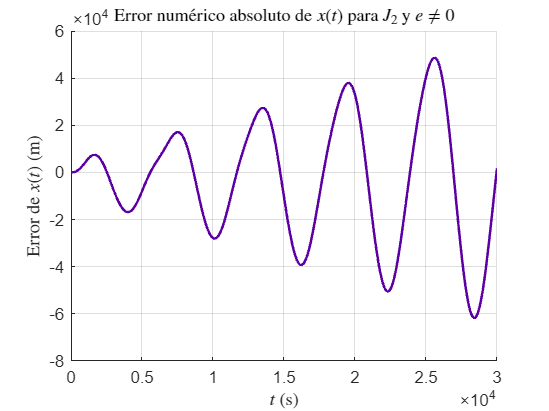

% Resolución
X0  = [ x0,  y0,  z0,  dx0,  dy0,  dz0];
X0I = [x0I, y0I, z0I, dx0I, dy0I, dz0I];
opts = odeset('RelTol', 1e-12, 'AbsTol', 1e-5);

[~, dXdt_Kepler] = ode113(@(t, X) odeKepler(X, mu), t, X0I, opts);
dXdt = cowellZonals(X0I, t, mu, R, [J2; 0; 0; 0; 0], opts);


FAM = AM + dXdt_Kepler;
rFAM = FAM(:, 1:3);

rX   = dXdt(:, 1:3);

% Comparación
plotNumericError(FAM(:,1), dXdt(:,1), t,       'Error num\''erico absoluto de $x(t)$ para $J_2$ y $e \neq 0$', ...
    '$t$ (s)',       'Error de $x(t)$ (m)', '#5C00A3');

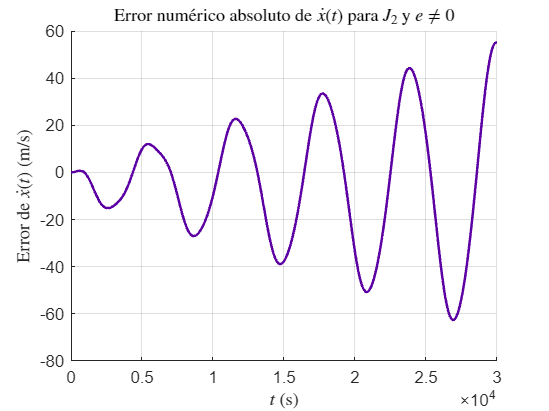

plotNumericError(FAM(:,4), dXdt(:,4), t, 'Error num\''erico absoluto de $\dot{x}(t)$ para $J_2$ y $e \neq 0$', ...
    '$t$ (s)', 'Error de $\dot{x}(t)$ (m/s)', '#5C00A3');

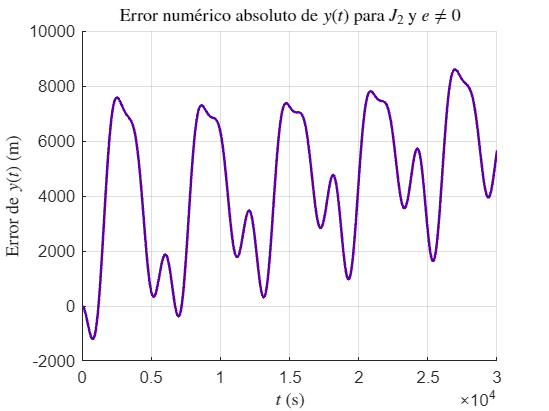

plotNumericError(FAM(:,2), dXdt(:,2), t,       'Error num\''erico absoluto de $y(t)$ para $J_2$ y $e \neq 0$', ...
    '$t$ (s)',       'Error de $y(t)$ (m)', '#5C00A3');

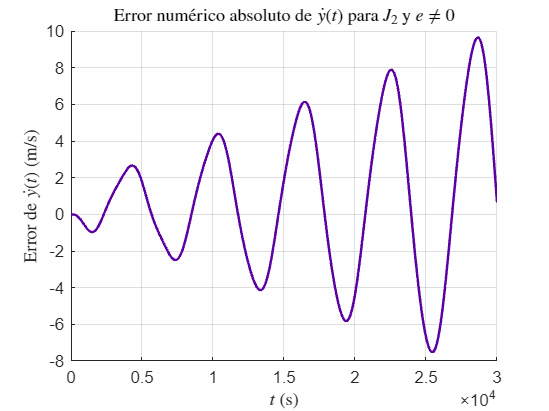

plotNumericError(FAM(:,5), dXdt(:,5), t, 'Error num\''erico absoluto de $\dot{y}(t)$ para $J_2$ y $e \neq 0$', ...
    '$t$ (s)', 'Error de $\dot{y}(t)$ (m/s)', '#5C00A3');

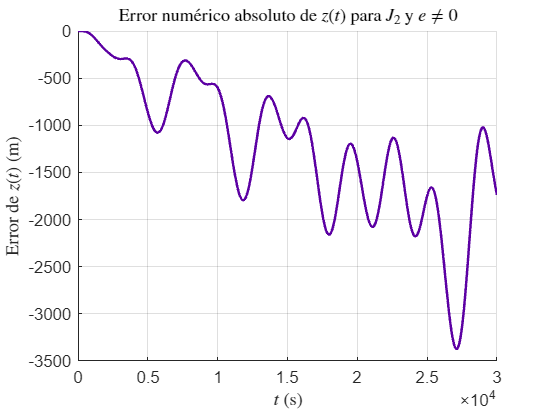

plotNumericError(FAM(:,3), dXdt(:,3), t,       'Error num\''erico absoluto de $z(t)$ para $J_2$ y $e \neq 0$', ...
    '$t$ (s)',       'Error de $z(t)$ (m)', '#5C00A3');

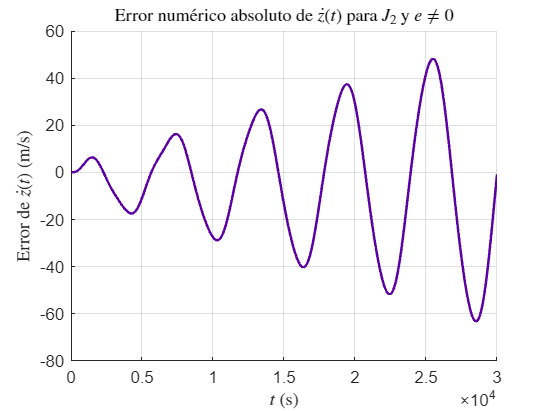

plotNumericError(FAM(:,6), dXdt(:,6), t, 'Error num\''erico absoluto de $\dot{z}(t)$ para $J_2$ y $e \neq 0$', ...
    '$t$ (s)', 'Error de $\dot{z}(t)$ (m/s)', '#5C00A3');

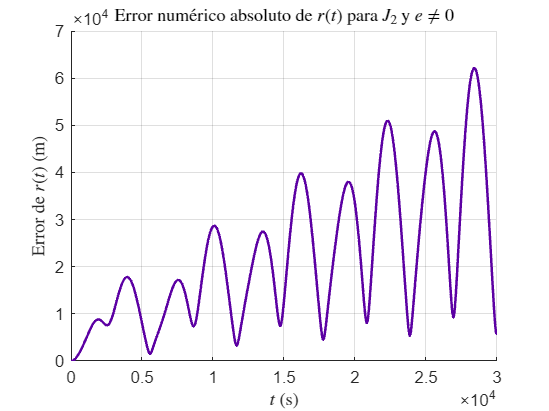


plotNumericErrorNorm(rFAM, rX, t, 'Error num\''erico absoluto de $r(t)$ para $J_2$ y $e \neq 0$', ...
    '$t$ (s)', 'Error de $r(t)$ (m)', '#5C00A3');

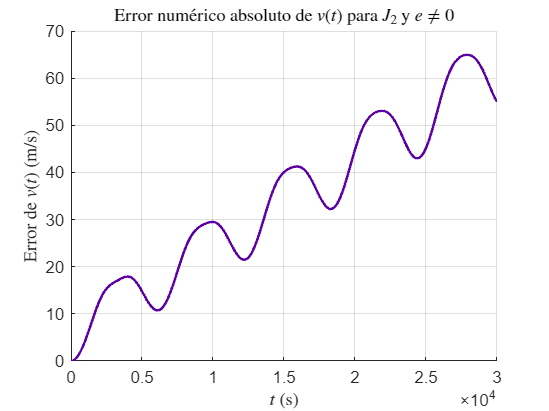

plotNumericErrorNorm(FAM(:, 4:6), dXdt(:, 4:6), t, 'Error num\''erico absoluto de $v(t)$ para $J_2$ y $e \neq 0$', ...
    '$t$ (s)', 'Error de $v(t)$ (m/s)', '#5C00A3');

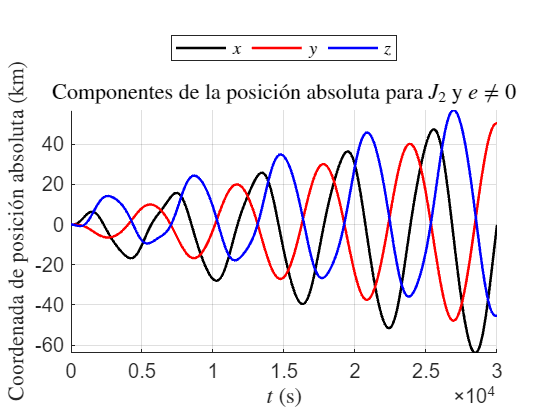




% Gráficos
plotMultiComparisons({xB / 10^3, yB / 10^3, zB / 10^3}, t, 'Componentes de la posici\''on absoluta para $J_2$ y $e \neq 0$', ...
    {'Coordenada de posici\''on absoluta (km)', '$t$ (s)'},  {'$x$', '$y$', '$z$'}, {'k', 'r', 'b'});

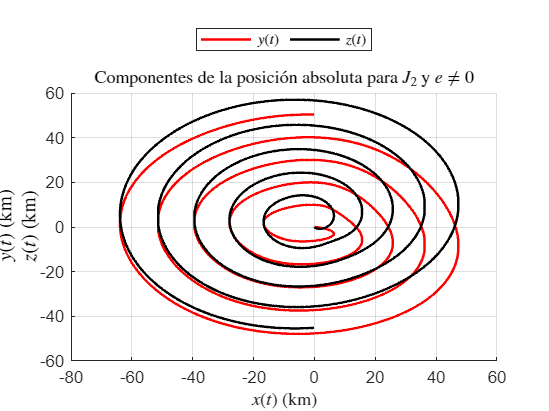

plotComparisons({xB / 10^3, yB / 10^3, zB / 10^3}, {'$x(t)$ (km)', '$y(t)$ (km)', '$z(t)$ (km)'}, ...
   'Componentes de la posici\''on absoluta para $J_2$ y $e \neq 0$', {'$y(t)$', '$z(t)$'}, {'r', 'k'});

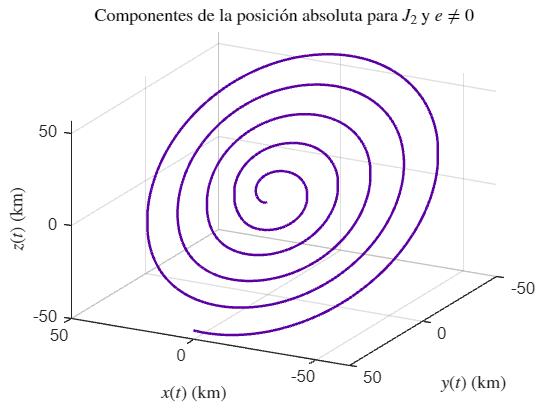

plot3D({xB / 10^3, yB / 10^3, zB / 10^3}, [-152 27], ...
    'Componentes de la posici\''on absoluta para $J_2$ y $e \neq 0$', ...
    {'$x(t)$ (km)', '$y(t)$ (km)', '$z(t)$ (km)'}, '#5C00A3');